# Analysis Pipeline for **Re-reference and Connectivity Methods Evaluation **

% set path
filename = which('ana_pipeline.mlx');
[filedir, ~, ~] = fileparts(filename);
cd(filedir);
addpath(genpath('./..')); % this should add analysis and matlab folder

This pipeline conducted a thorough evaluation of various re-reference and connectivity methouds. The results may offer suggestions and recommendations for method selection. 

Specific evaluation aspects include:

- Method similarity 

- Spurious correlation

- Sensitivity to electrode removal

- SOZ lateralization

## 0 | Settings 🤖

This part finish the pasic setting for the pipeline, including select the methods to be evaluated and the dataset to use.

% initialize params
allRefMethods = {'car','bipolar','laplacian'}; 
allRefNames = {'Common average reference', 'Bipolar reference','Laplacian reference'};
% Create a map of function handles
refMap = containers.Map(allRefMethods, {@common_average_reference, ...
                                        @bipolar_montage, ...
                                        @laplacian_reference});

allConnMeasures = {'pearson','squaredPearson','crossCorr','coh','plv','relaEntropy'};
allConnMeasureNames = {'Pearson','Squared Pearson','Cross Corr','Coherence','PLV','Relative Entropy'};
connMap = containers.Map(allConnMeasures, {@new_pearson_calc, ...
                                           @new_pearson_calc, ...
                                           @cross_correlation, ...
                                           @faster_coherence_calc, ...
                                           @plv_calc, ...
                                           @relative_entropy});
numFeatsMap = containers.Map(allConnMeasures,[1,1,1,7,7,7]);

🟡Select Re-reference Methods you want to evaluate:

% select methods you want to compare
ifRef = [true, 
         true, 
         false];
global refMethods refNames
refMethods = allRefMethods(ifRef);
refNames = allRefNames(ifRef);

🟡Select Connectivity Methods you want to evaluate:

% select connectivity methods you want to compare
ifConn = [true, 
          true, 
          true,
          true,
          true,
          true];
global connMeasures connMeasureNames numFeats freqBands freqBandNames 
global nMethod nRef nConn nFreq
connMeasures = allConnMeasures(ifConn);
connMeasureNames = allConnMeasureNames(ifConn);
% update number of features
numFeats = [];
for i = connMeasures
    numFeats = [numFeats, numFeatsMap(i{1})];
end
freqBands = {'\delta','\theta','\alpha','\beta','\gamma','Ripple','All'};
freqBandNames = {'delta','theta','alpha','beta','gamma','ripple','broad'};
nMethod = length(refMethods)*sum(numFeats);
nRef = length(refMethods);
nConn = length(connMeasures);
nFreq = length(freqBands);

🟡Select Dataset to use:

allDataset = {'HUP','MUSC'};
dataset = 'HUP';

🟡Path to store results:

global resultDir rawPath dataPath figPath MLPath
resultDir = "HUP";
rawPath = strcat(resultDir,'/raw');
dataPath = strcat(resultDir,'/data');
figPath = strcat(resultDir,'/figs');
MLPath = strcat(resultDir,'/ML');
for path = {resultDir,rawPath,dataPath,figPath,MLPath}
    if exist(path{1},'dir') == 0
        mkdir(path{1});
    end
end
addpath(genpath(resultDir));
 
% Do dataset processing here!!
% Assume there's a function that can fetch metaData
% and save in the tools/files folder, which should be named
% dataset_metaDataFull.mat
% Here, reate a patientList file containing selected patients, if not already
% exising; then save it to patientList to store other info
if exist(strcat(dataset,'_patientList.mat'),'file') ~= 2
    select_patient(dataset);
    load(strcat('meta/',dataset,'_patientList.mat'));
else
    load(strcat('meta/',dataset,'_patientList.mat'));
end
numFile = length(patientList);

% an array for easy channel mapping
indArray = repmat(num2cell([1:12]'),1,3); 
indArray = cellfun(@(x) num2str(x),indArray,'UniformOutput',false);

According to your selection, there will be:

% print some basic characteristics
fprintf('%d files ✖️%d Re-ref methods ✖️%d Connectivity Mesures\n',numFile,length(refMethods),length(connMeasures))

111 files ✖️2 Re-ref methods ✖️6 Connectivity Mesures


fprintf('Due to calculation over different frequency bands,\n')

Due to calculation over different frequency bands,


fprintf('The %d Connectivit Measures translates to %d total methods\n',length(connMeasures),sum(numFeats))

The 6 Connectivit Measures translates to 24 total methods


## 1 | Download Data ⬇️

This part downloads data clips from the specified dataset and finish initial pre-processing, including bad-channel rejection and notch filtering. This step can be skipped if the data were already downloaded.

 
%% step1 download data and update patientList with sampling information
% if want to rerun this step, restore to the original version as later 
% processing would change patientList
load(strcat('meta/',dataset,'_subMeta.mat'));
patientList = subMeta;
keepPatient = zeros(numFile,1);

bar = waitbar(0, 'Processing...');
for i = 1:numFile
    waitbar(i/numFile, bar, sprintf('Processing %d of %d...', i, numFile));
    % skip the file if don't have file start time
    if isnan(patientList(i).ind_2pm)
        continue
    end

    % start from the first file available
    if patientList(i).fileNo == 1
        % construct channel map
        chanMatL = strcat(repmat({'L'},12,3), ...
                         repmat({patientList(i).tofindA, ...
                                 patientList(i).tofindB, ...
                                 patientList(i).tofindC},12,1), ...
                         indArray);
        chanMatR = strcat(repmat({'R'},12,3), ...
                         repmat({patientList(i).tofindA, ...
                                 patientList(i).tofindB, ...
                                 patientList(i).tofindC},12,1), ...
                         indArray);
        
        % channels to be downloaded
        selecElecs = [chanMatL(logical(patientList(i).elecInd'));chanMatR(logical(patientList(i).elecInd'))];
        [data,labels,fs,elecIndNew,keepPatient(i),sampleInfo] = preprocess(patientList(i),selecElecs);
        patientList(i).time = sampleInfo.time;
        patientList(i).bad = sampleInfo.bad;
        patientList(i).elecInd = elecIndNew;
        patientList(i).keep = keepPatient(i);
        if keepPatient(i) == 0
            continue
        end
        save(strcat(rawPath,'/',patientList(i).patient,'.mat'),'data','labels','fs','elecIndNew','sampleInfo')
    else
        ind = patientList(i).fileNo;
        keepPatient(i) = 0;
        if all(keepPatient(i-ind+1:i-1) == zeros(ind-1,1))
            chanMatL = strcat(repmat({'L'},12,3), ...
                         repmat({patientList(i).tofindA, ...
                                 patientList(i).tofindB, ...
                                 patientList(i).tofindC},12,1), ...
                         indArray);
            chanMatR = strcat(repmat({'R'},12,3), ...
                             repmat({patientList(i).tofindA, ...
                                     patientList(i).tofindB, ...
                                     patientList(i).tofindC},12,1), ...
                             indArray);
            selecElecs = [chanMatL(logical(patientList(i).elecInd'));chanMatR(logical(patientList(i).elecInd'))];
            [data,labels,fs,elecIndNew,keepPatient(i),sampleInfo] = preprocess(patientList(i),selecElecs);
            patientList(i).time = sampleInfo.time;
            patientList(i).bad = sampleInfo.bad;
            patientList(i).elecInd = elecIndNew;
            patientList(i).keep = keepPatient(i);
            if keepPatient(i) == 0
                continue
            end
            save(strcat(rawPath,'/',patientList(i).patient,'.mat'),'data','labels','fs','elecIndNew','sampleInfo')
        end
    end
end

IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****


close(bar);
save(strcat('meta/',dataset,'_patientList.mat'),'patientList');

## 2 | Re-ref and Calculate Connectivity 🔣 

This part conduct re-ref processing and calculate connectivity for all methods.

 

%% step2 - reference, connectivity and save raw results
results = NaN(numFile,nRef,sum(numFeats),36,36,2);
bar = waitbar(0, 'Processing...');
for i = 1:numFile
    waitbar(i/numFile, bar, sprintf('Processing %d of %d...', i, numFile));
    if patientList(i).keep == 1
        % load data
        filename = strcat(rawPath,'/',patientList(i).patient,'.mat');
        if exist(filename,'file')
            load(filename)
            for j = 1:nRef
                [values,newlabels,elecIndNew,keepPatient(i)] = calcRef(data,labels,refMethods{j},patientList(i).elecInd);
                if keepPatient(i) == 0
                    continue
                end
                for k = 1:nConn
                    out = calcConn(values,fs,connMeasures{k},elecIndNew,2,1);
                    results(i,j,sum(numFeats(1:k-1))+1:sum(numFeats(1:k-1))+numFeats(k),:,:,:) = permute(out,[3,1,2,4]);
                end
            end
        end
    end
end
close(bar);
keep = [patientList.keep]';
results(~logical(keep),:,:,:,:,:) = [];
save(strcat(dataPath,'/results.mat'),'results','keep');

Error using save
'/results.mat' is not a valid variable name.

fprintf('Finished calculation\n');
fprintf('There are %d unique patients included\n',size(results,1));

## 3 | Methods Similarity 🔍

This part evaluate which methods are more similar to each other

%% step3 - calculate measure correlation
 
% load results
if exist(strcat(dataPath,'/results.mat'),'file') ~= 2
    error('No results file exist, please make sure to run section 2.')
else
    load(strcat(dataPath,'/results.mat'));
end

% patient list
patients = {patientList.patient};
patients = patients';
patients(~logical(keep))=[];

% index for network extraction
ind = find(triu(ones(36,36), 1)); 
for i = 1:size(results,1)
    % for each patient, reshape
    tmp = results(i,:,:,:,:,:);
    tmp = reshape(tmp,[nRef,sum(numFeats),36,36,2]);
    tmp = permute(tmp,[2,1,3,4,5]);
    tmp = reshape(tmp,[nMethod,36,36,2]);
    % network level
    tmpNet = reshape(tmp,[nMethod,36*36,2]);
    tmpNet = tmpNet(:,ind,:);
    tmpNet = reshape(tmpNet,[nMethod,length(ind)*2]);
    networkCorr(i,:,:) = corrcoef(tmpNet','Rows','complete');
    % node level
    nodeStr = [];
    for j = 1:36
        nodeStr(:,j,1) = nanmean(tmp(:,j,[1:(j-1),(j+1):end],1),3);
        nodeStr(:,j,2) = nanmean(tmp(:,j,[1:(j-1),(j+1):end],2),3);
    end
    nodeStr = reshape(nodeStr,[nMethod,36*2]); 
    nodeCorr(i,:,:) = corrcoef(nodeStr','Rows','complete');
    % global level
    globalStr(:,i) = nanmean(nodeStr,2);
end
globalCorr = corrcoef(globalStr','Rows','complete');
save(strcat(dataPath,'/corrs.mat'),'networkCorr','nodeCorr','globalStr','globalCorr','patients')

Run this part if you would like to generate plots for section 3.

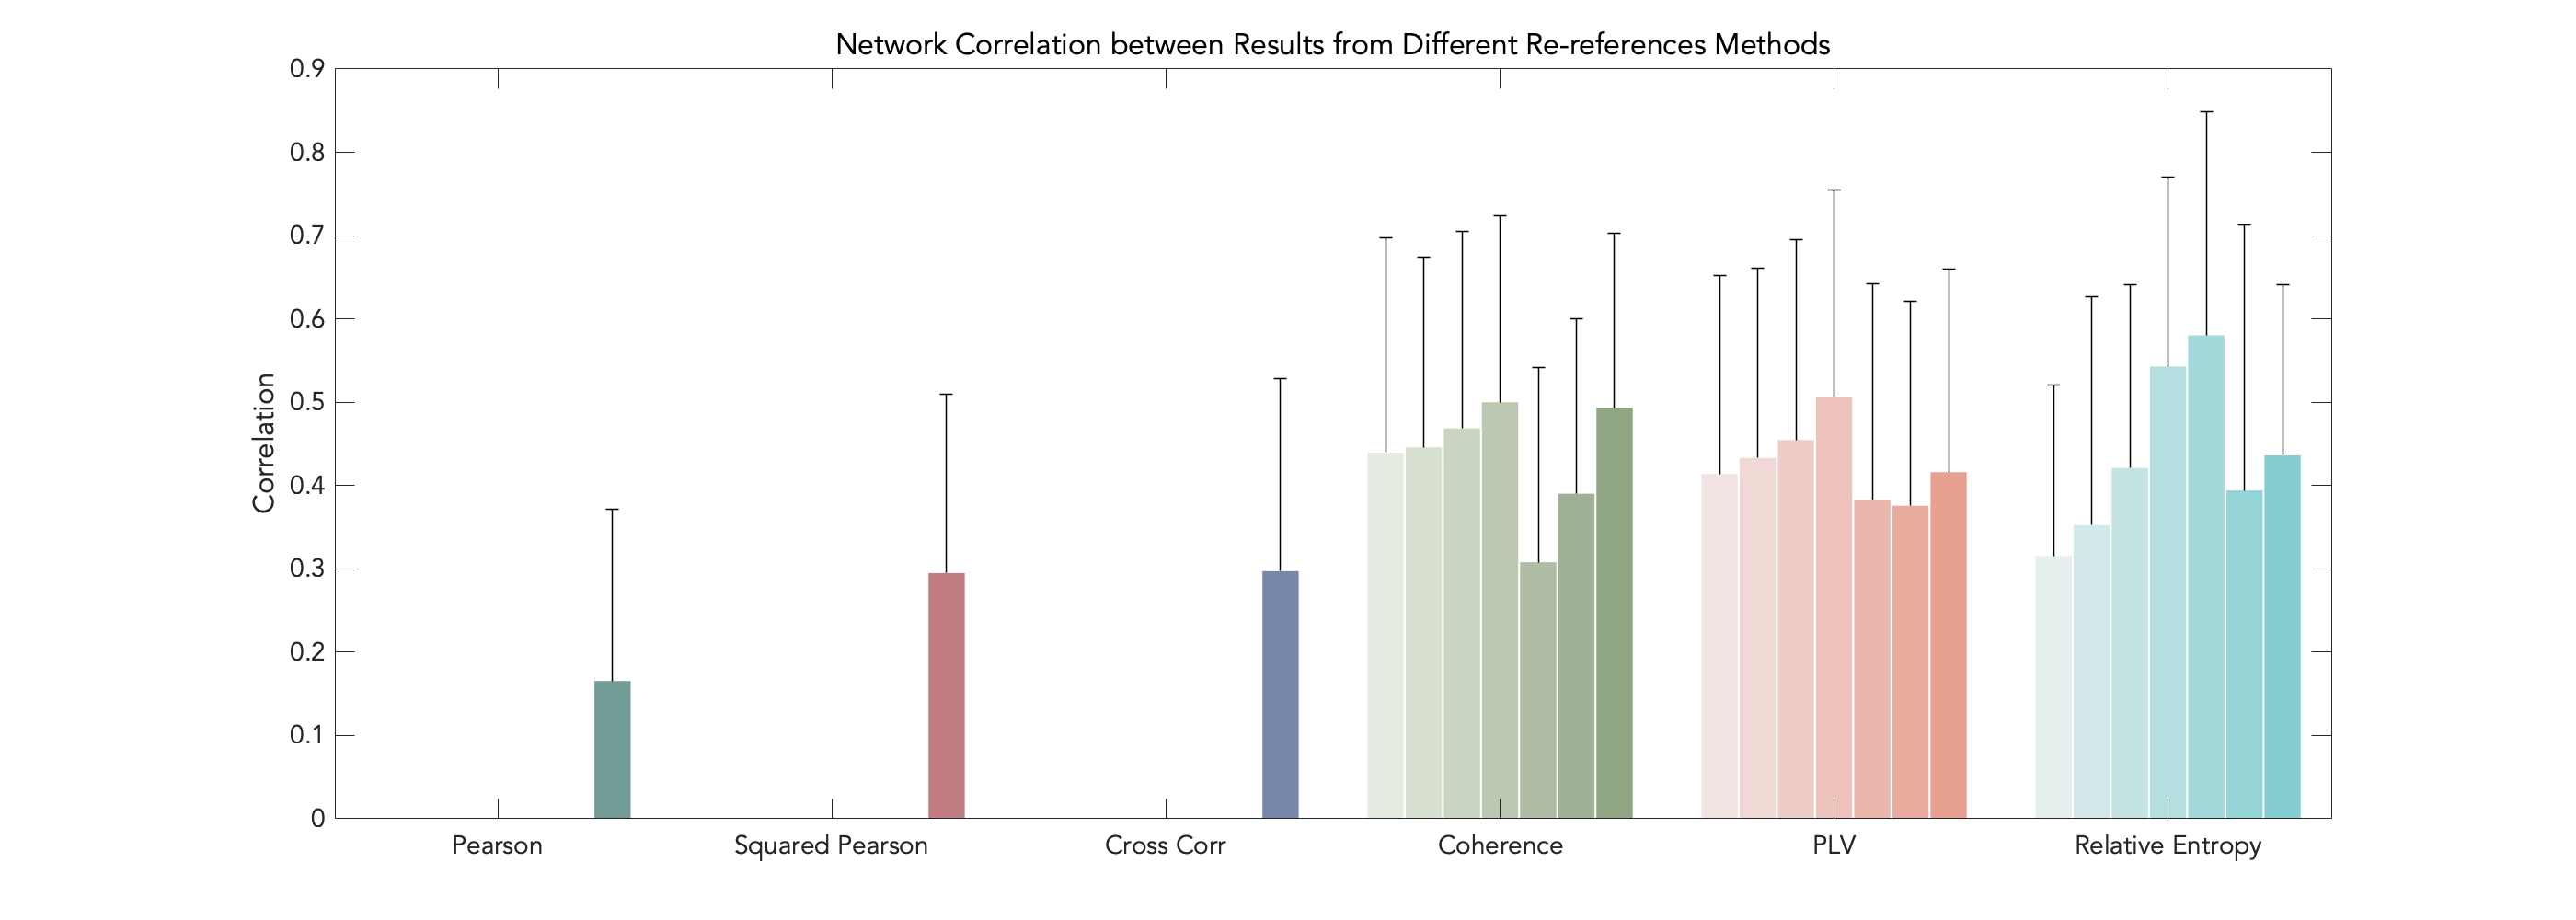

% plot for section 3
%%%% WARNING only suitable for 2x24 setting, need generalize!!!
 
% load results
if exist(strcat(dataPath,'/corrs.mat'),'file') ~= 2
    error('No results file exist, please make sure to run section 3.')
else
    load(strcat(dataPath,'/corrs.mat'));
end
% per patient plot
plot_corrs(networkCorr,patients,'Network');
plot_corrs(nodeCorr,patients,'Nodal');
plot_corrs(globalCorr,patients,'Global');
% clustering plot
plot_clustergram(globalCorr,'Global');
plot_clustergram(squeeze(mean(networkCorr,1,'omitnan')),'Network');
plot_clustergram(squeeze(mean(nodeCorr,1,'omitnan')),'Nodal');
% decomposed plots
% break down large correlation map by ref/frequency/method, etc.
% 1. by reference
% compare how much the results differs for different
% reference, higher corr indicates higher similarity between references
% build a matrix to extract lower left diagonal
mat = zeros(nMethod,nMethod);
mat(nMethod/2+1:nMethod,1:nMethod/2) = mat(nMethod/2+1:nMethod,1:nMethod/2) + eye(nMethod/2);
ind = find(mat);
% extract refcorr
refcorr_network = networkCorr(:,ind);
refcorr_node = nodeCorr(:,ind);
refcorr_global = globalCorr(ind);
save(strcat(dataPath,'/byref.mat'),'refcorr_network','refcorr_node','refcorr_global')
% network level
data = nanmean(refcorr_network,1);   
error = nanstd(refcorr_network,1);
plot_by_ref(data,error,'Network');

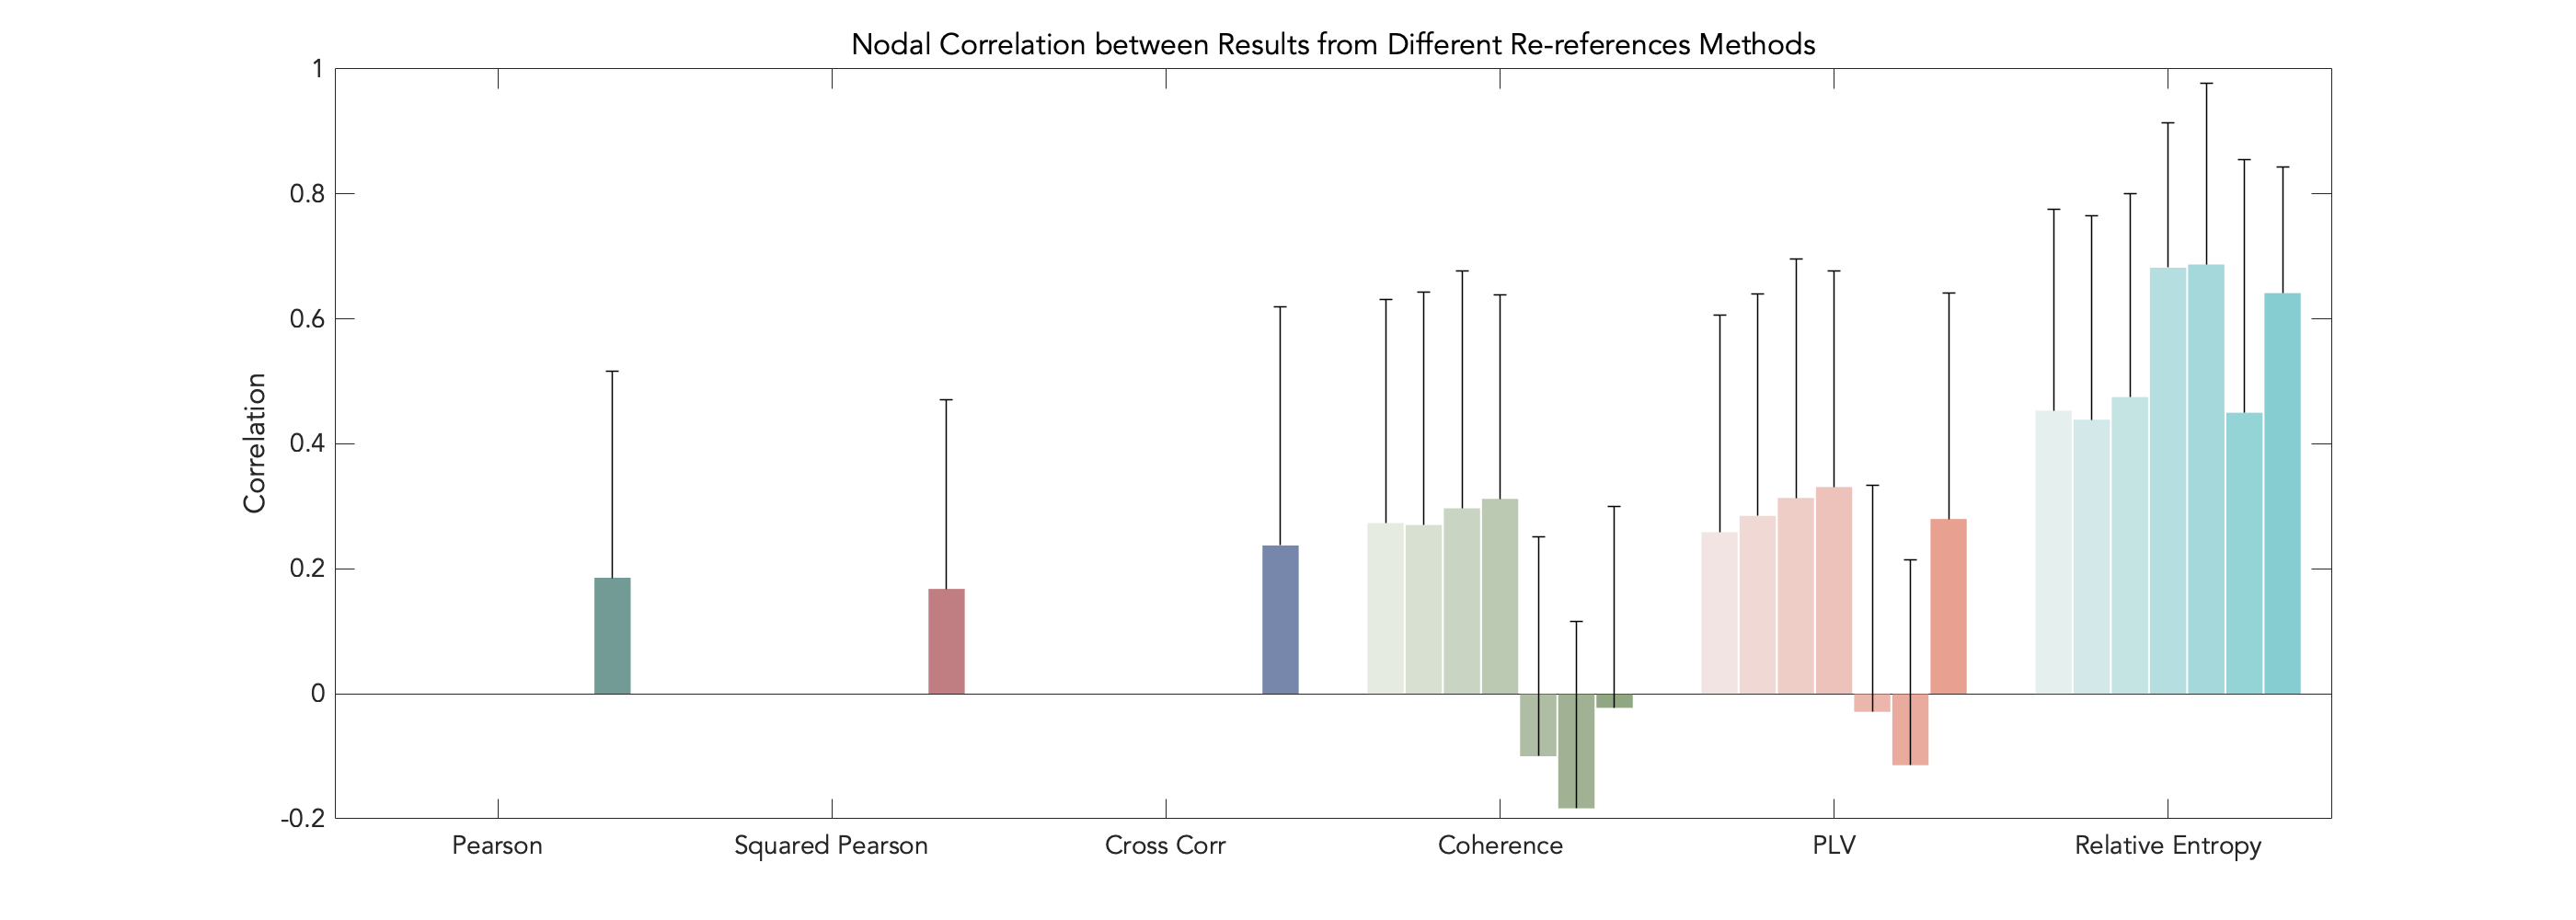

% nodal
data = nanmean(refcorr_node,1);   
error = nanstd(refcorr_node,1);
plot_by_ref(data,error,'Nodal');

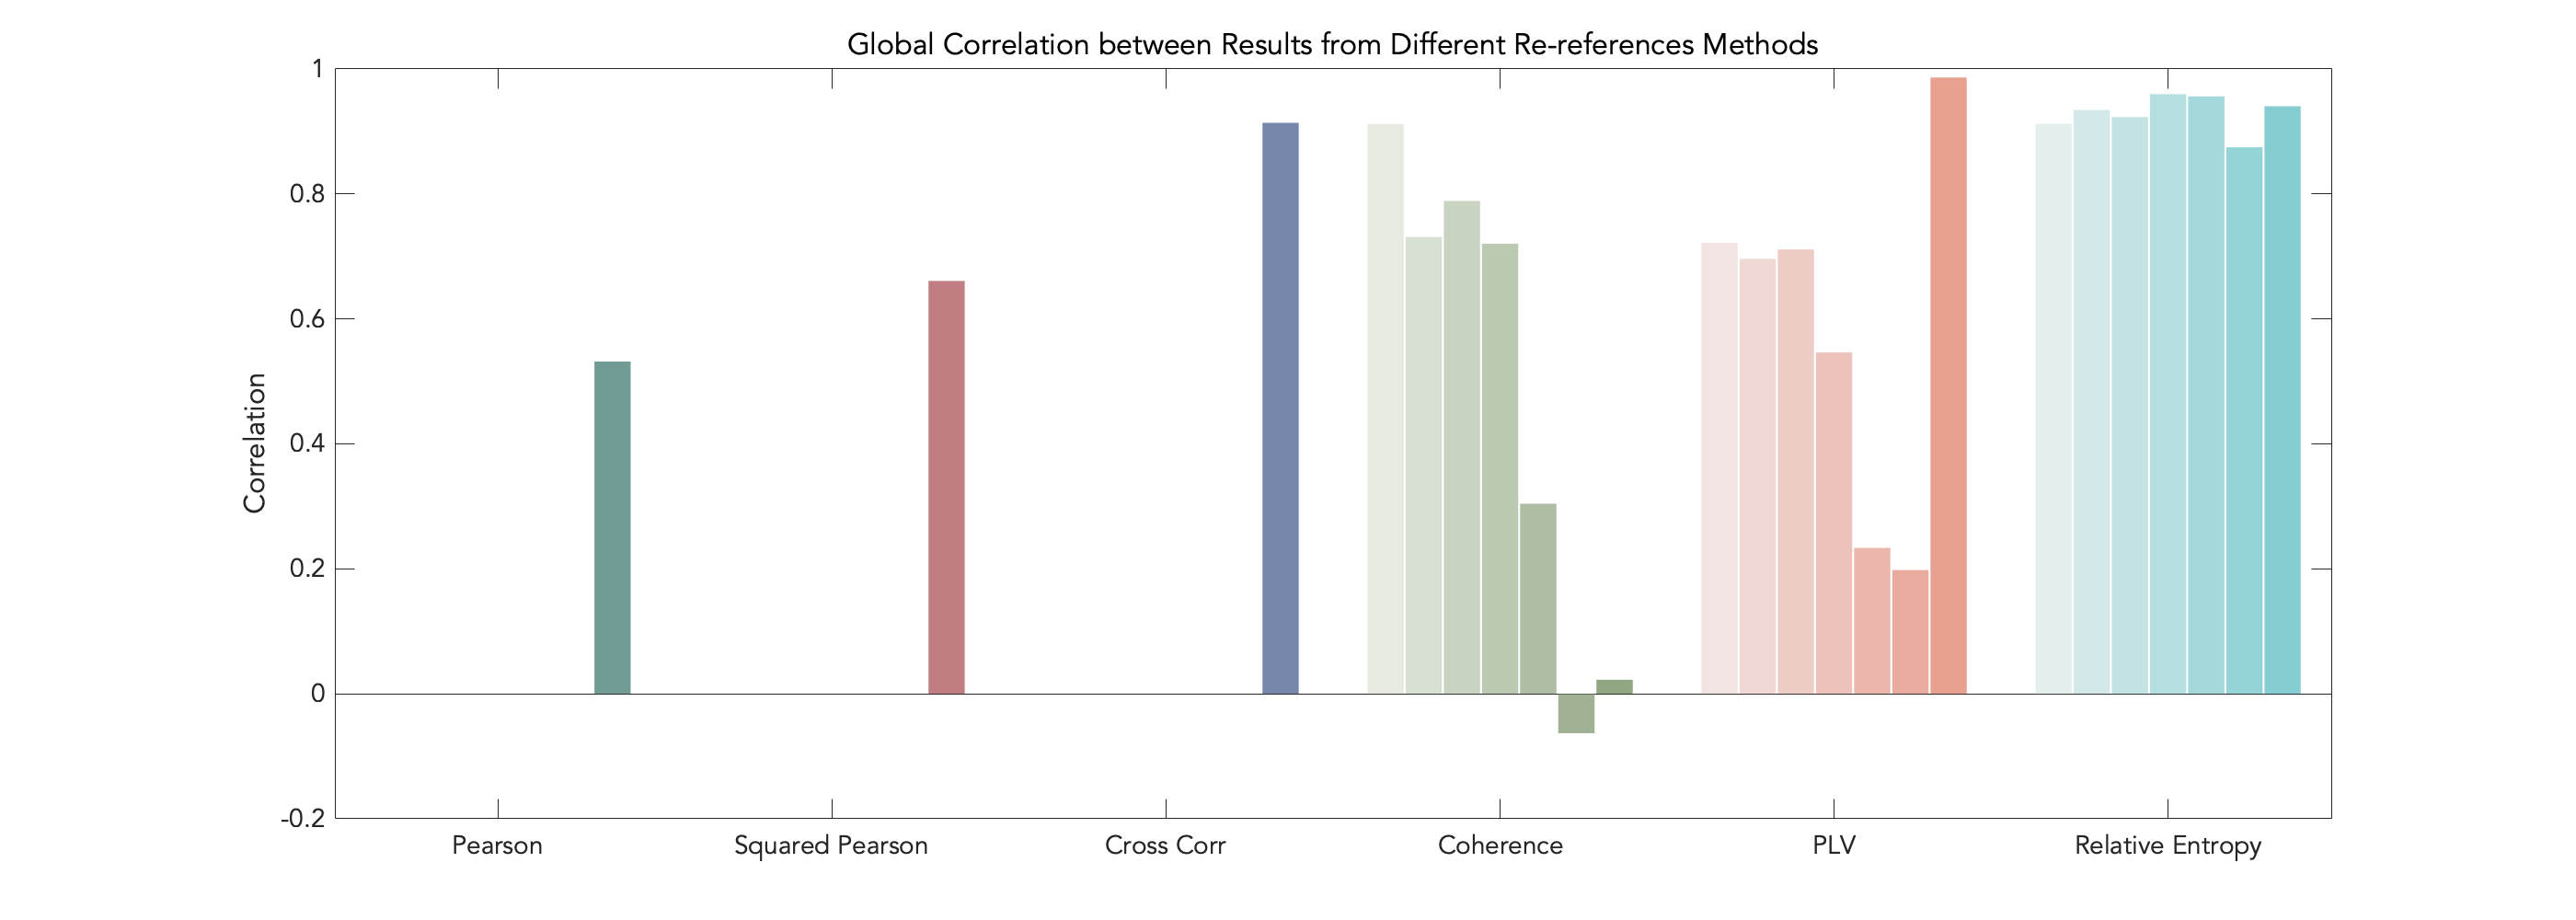

% global
data = refcorr_global';
error = nan(size(data));
plot_by_ref(data,error,'Global');

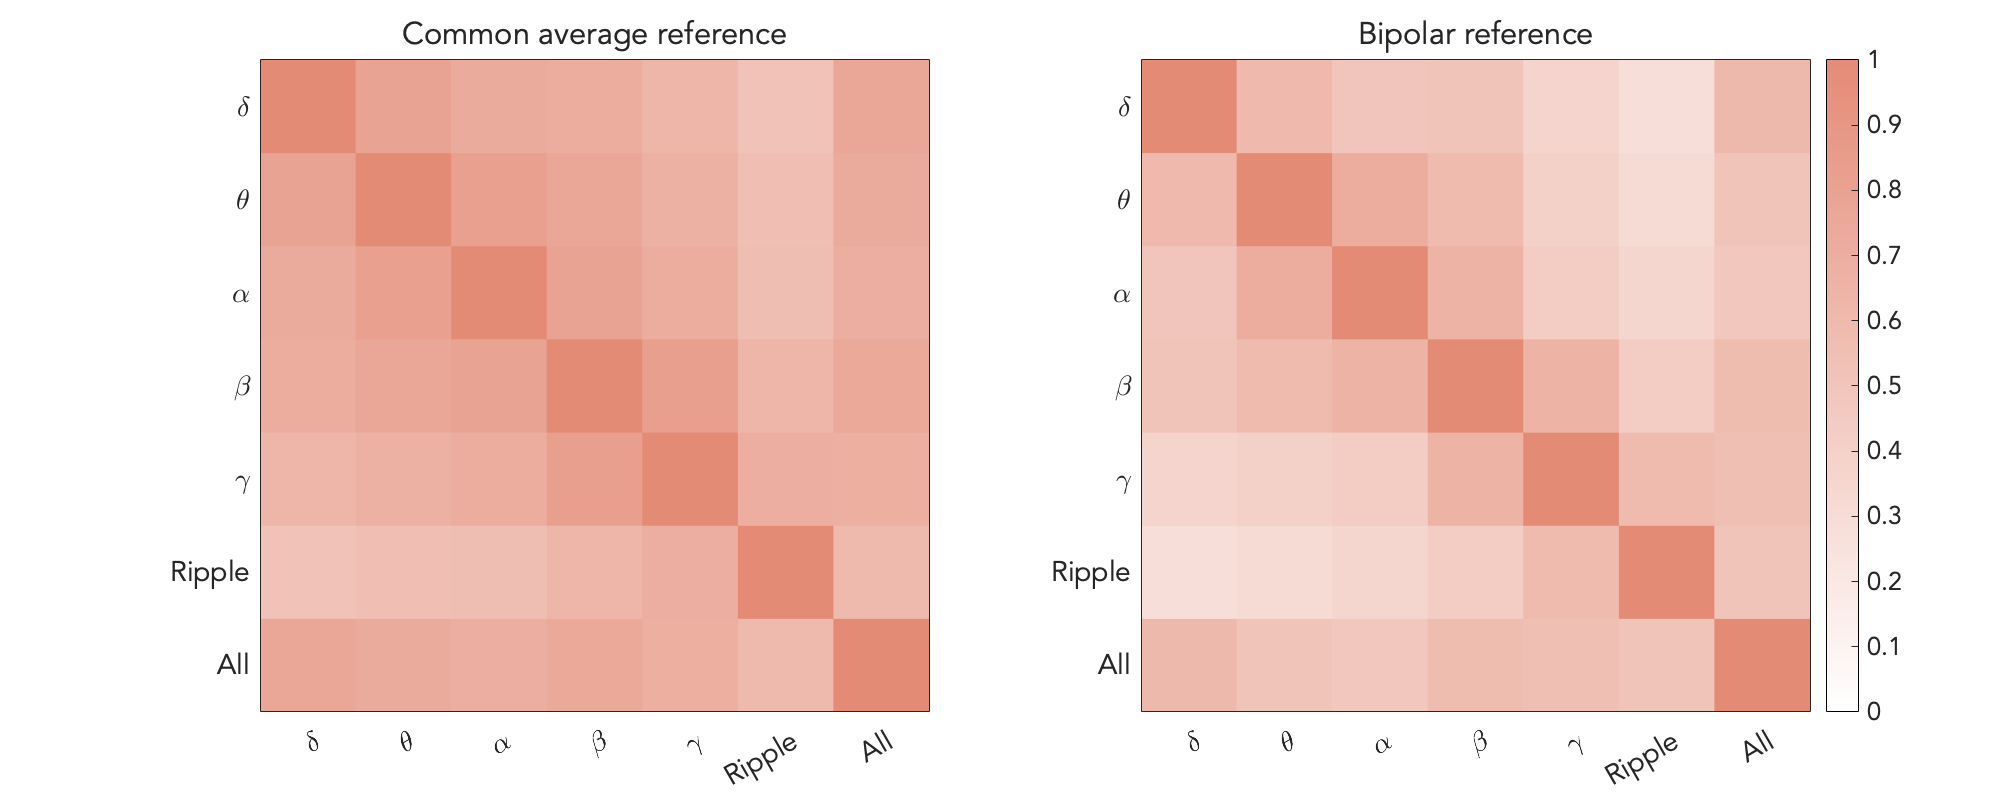

% 2. by frequency
% compare how much the results differs for different
% frequency band (within each method), higher corr indicates higher 
% similarity between frequency bands, but because there's multiple
% freuqency bands, can no longer use scatter/bar plot, there's a matrix
freqcorr_network = [];
freqcorr_node = [];
freqcorr_global = [];
ind = [];
for i = 1:nConn
    if numFeats(i) == 7
        ind = [ind, sum(numFeats(1:i-1))];
    end
end
ind = [ind, ind+sum(numFeats)];
for i = ind
    freqcorr_network = [freqcorr_network;networkCorr(:,i+1:i+nFreq,i+1:i+nFreq)];
    freqcorr_node = [freqcorr_node;nodeCorr(:,i+1:i+nFreq,i+1:i+nFreq)];
    freqcorr_global = [freqcorr_global;reshape(globalCorr(i+1:i+nFreq,i+1:i+nFreq),1,nFreq,nFreq)];
end
save(strcat(dataPath,'/byfreq.mat'),'freqcorr_network','freqcorr_node','freqcorr_global')
plot_by_freq(freqcorr_network,'Network');

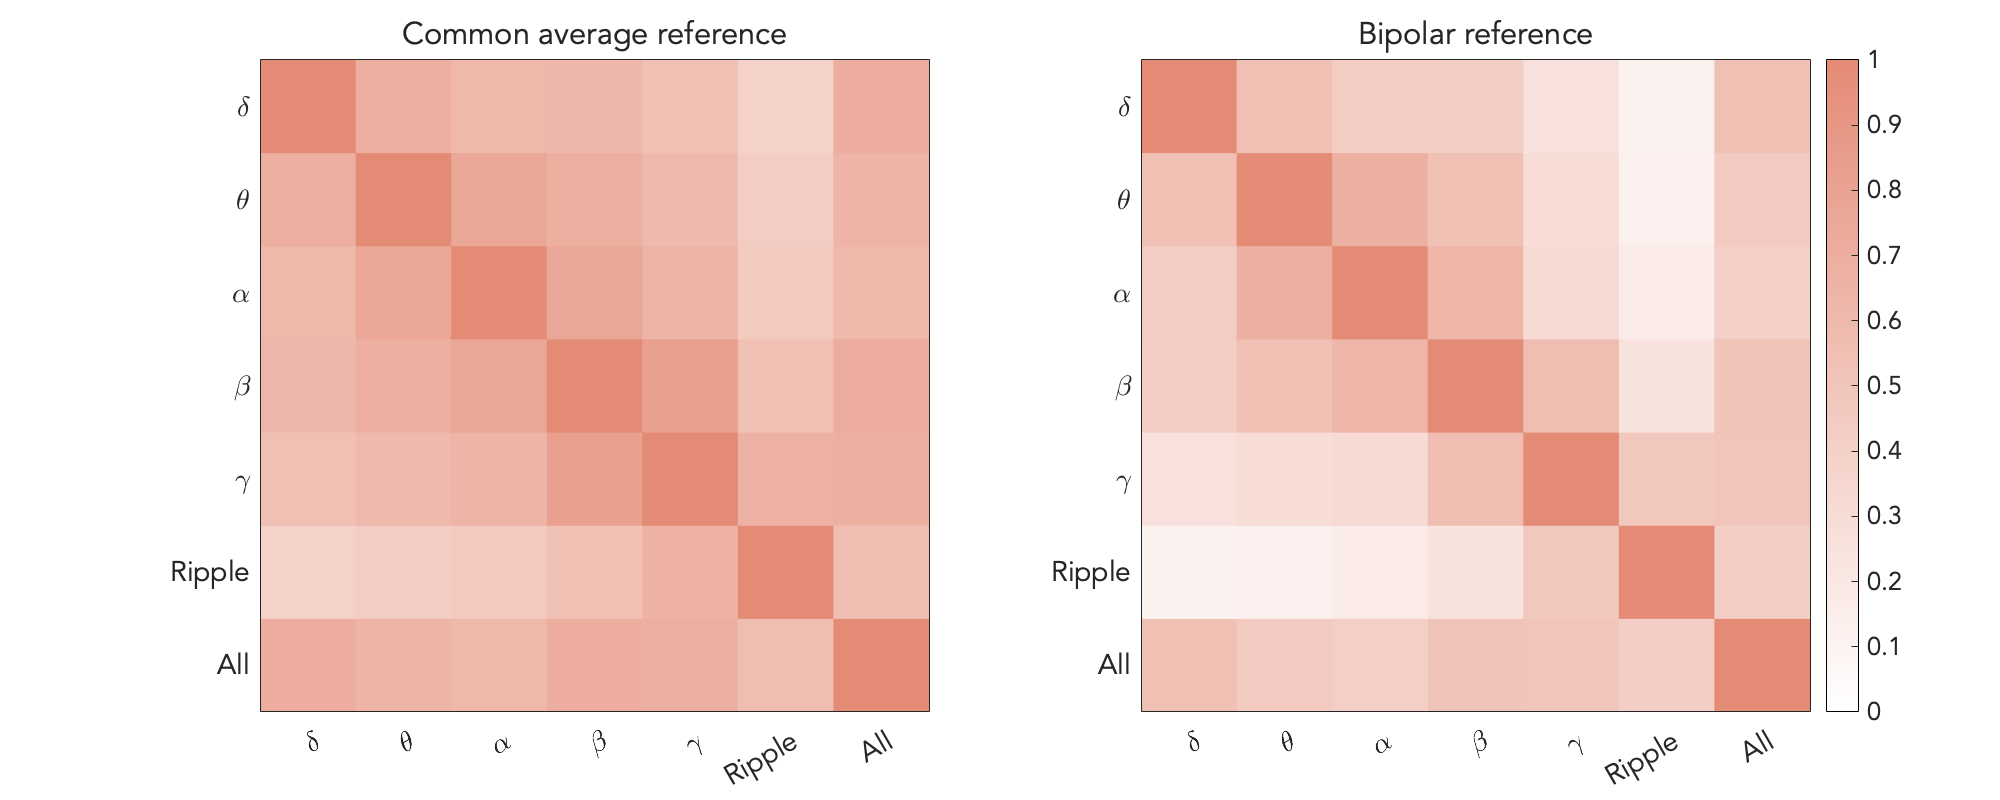

plot_by_freq(freqcorr_node,'Nodal');

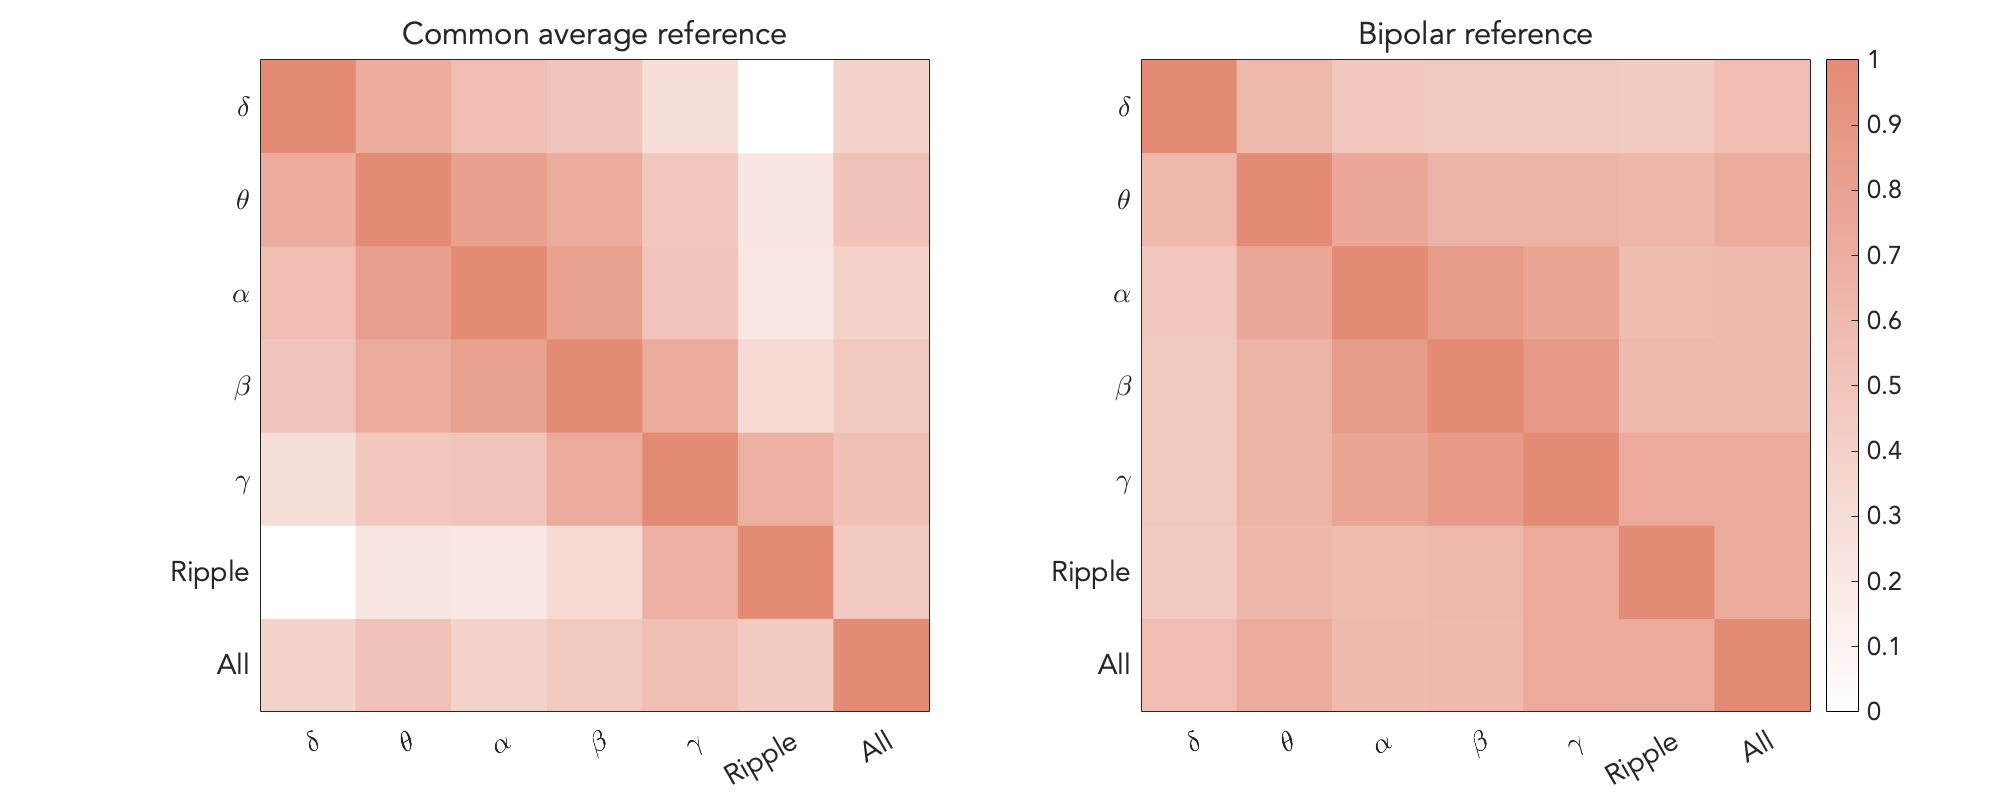

plot_by_freq(freqcorr_global,'Global');

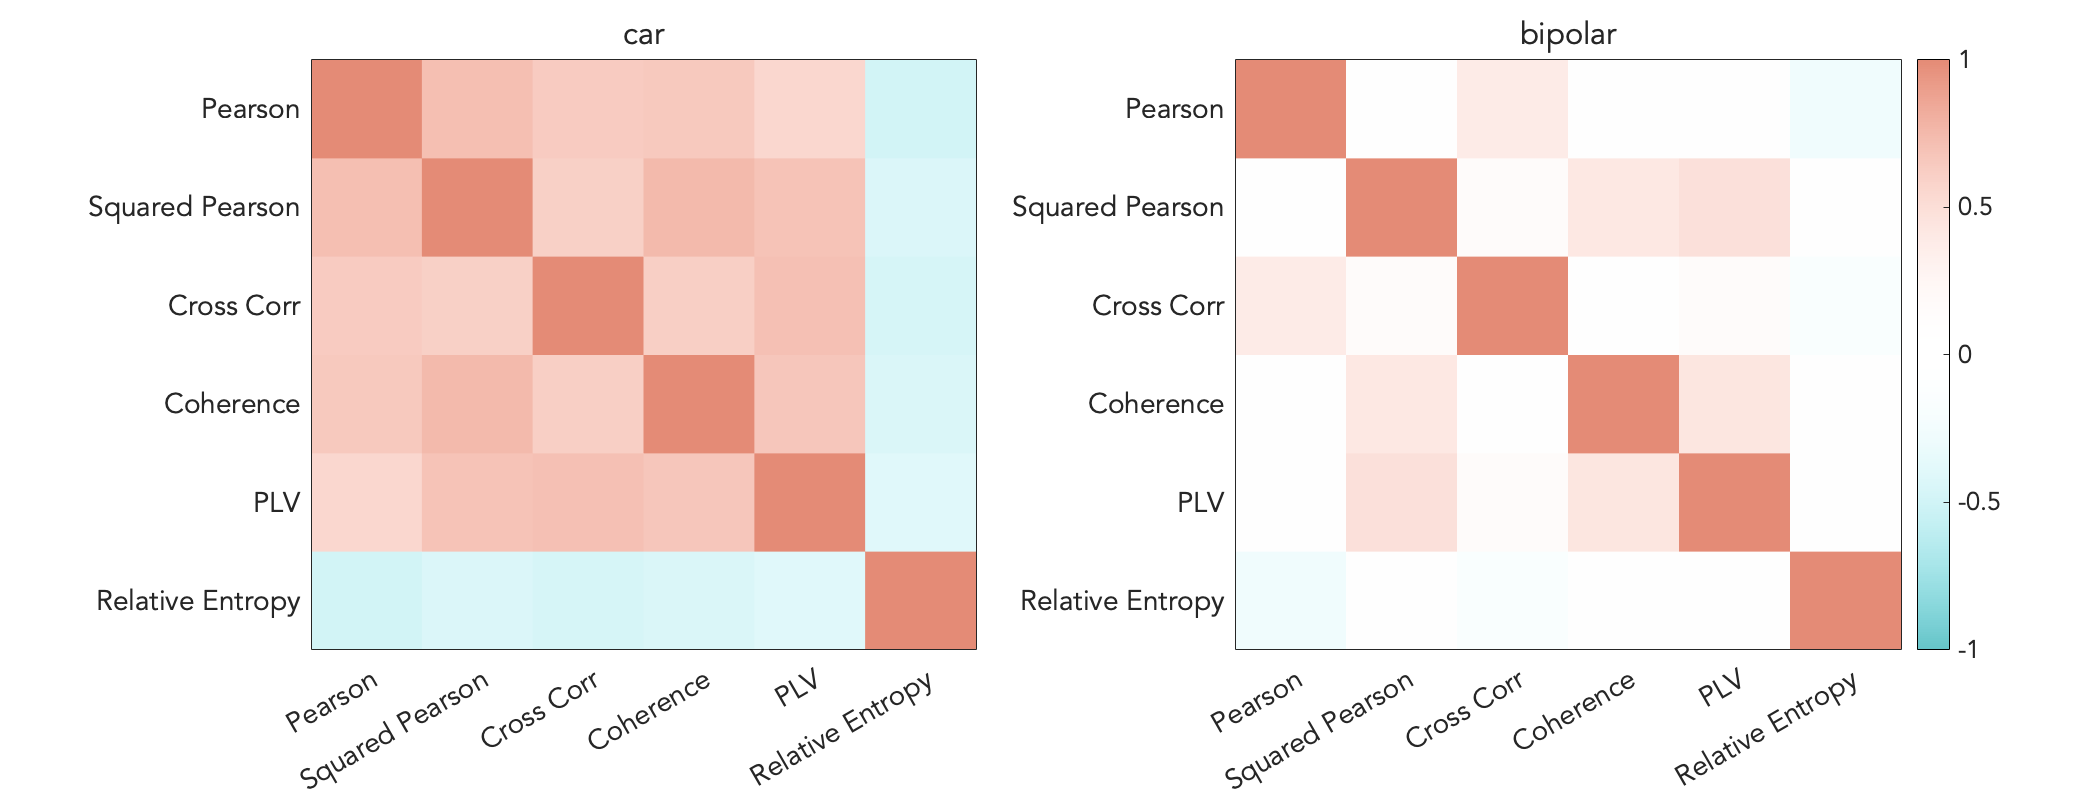

%% 3. by method
% compare how much the results differs for different
% method (within each frequency band), higher corr indicates higher 
% similarity between methods, concat of patients X frequency X ref
plot_by_method(networkCorr,'Network');

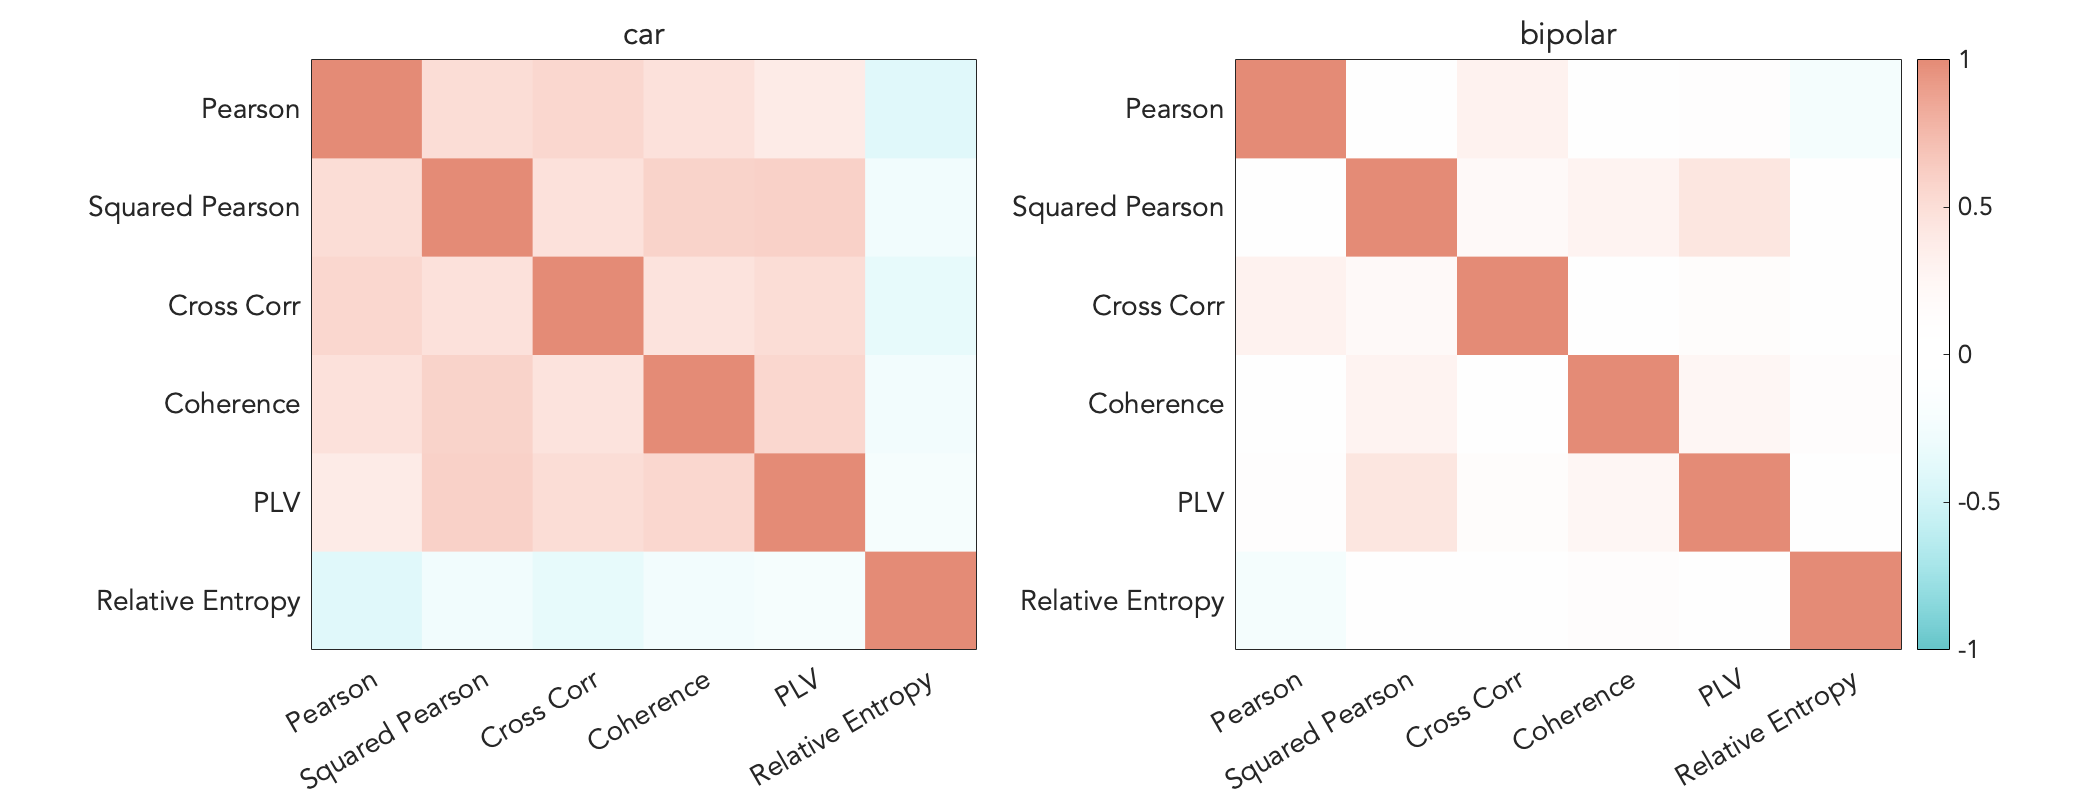

plot_by_method(nodeCorr,'Nodal');

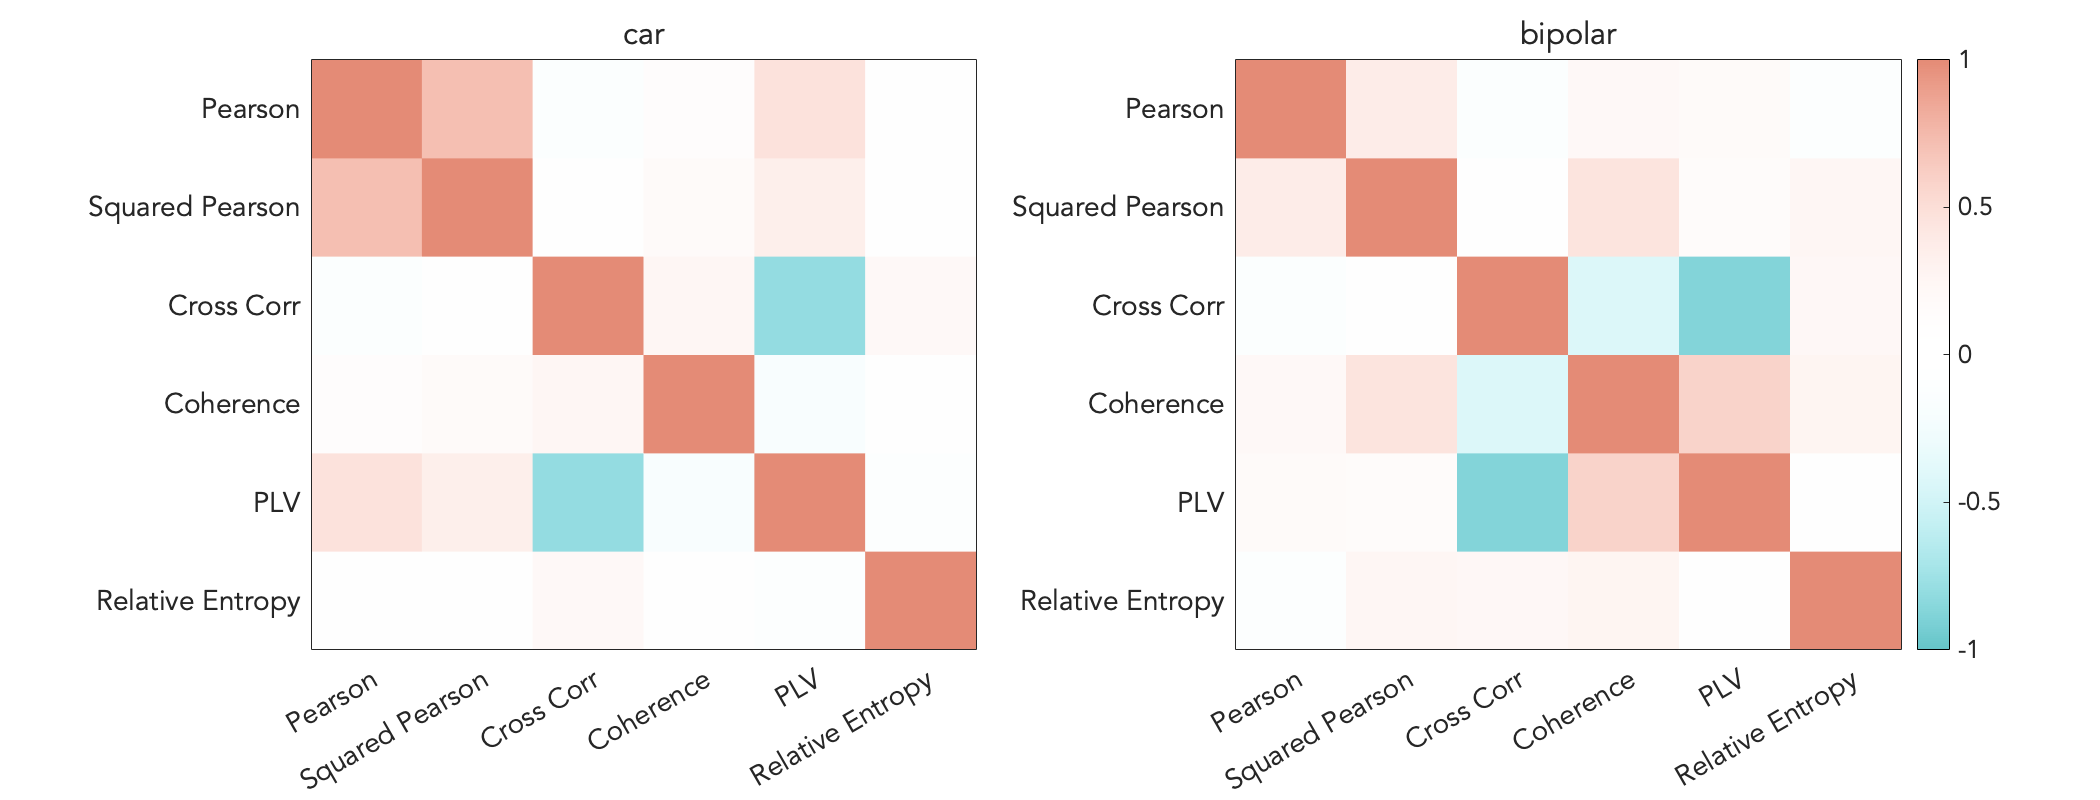

plot_by_method(reshape(globalCorr,1,nMethod,nMethod),'Global');

## 4 | Spurious correlation 📈

This part evaluate which re-ref method may introduce spurious correlation

Note: This part is dependent on fieldtrip toolbox, so please specify your fieldtrip toolbox folder

 
% load toolbox
ftpath = "/Users/meow/Downloads/fieldtrip-20230118";
addpath(ftpath);
ft_defaults
% simulate data 16 chans
% uncorrelated, without recording reference
cfg = [];
cfg.method = 'linear_mix';
cfg.ntrials = 100;
cfg.triallength = 2;
cfg.fsample = 512;
cfg.nsignal = 16;
cfg.bpfilter = 'yes';
cfg.bpfreq = [8 80];
cfg.blc = 'yes';
cfg.mix = eye(16);
cfg.delay = zeros(16,16);
cfg.absnoise = 1;
data1 = ft_connectivitysimulation(cfg);

Bandpass filtering data: onepass-zerophase, order 846, hamming-windowed sinc FIR
  cutoff (-6 dB) 8 Hz and 80 Hz
  transition width 2.0 Hz, stopband 0-7.0 Hz, passband 9.0-79.0 Hz, stopband 81.0-256 Hz
  maximum passband deviation 0.0022 (0.22%), stopband attenuation -53 dB
the call to "ft_connectivitysimulation" took 3 seconds and required the additional allocation of an estimated 195 MB


% with recording reference
cfg.mix = [eye(16),ones(16,1)];
cfg.delay = zeros(16,17);
data2 = ft_connectivitysimulation(cfg);
%re-reference
data1car = data1;
data2car = data2;
data1bp = data1;
data2bp = data2;
elecIndnew = zeros(3,12);elecIndnew(1,1:8)=1;
chanMatL = strcat(repmat({'L'},12,3), ...
                         indArray);
chanMatR = strcat(repmat({'R'},12,3), ...
                 indArray);
labels = [chanMatL(logical(elecIndnew'));chanMatR(logical(elecIndnew'))];  
for i = 1:100
    data = data1.trial{1,i}';
    [values,~,~,~] = calcRef(data,labels,refMethods{1},elecIndnew);
    data1car.trial{1,i} = values';
    [values,~,~,~] = calcRef(data,labels,refMethods{2},elecIndnew);
    data1bp.trial{1,i} = values';
    data = data2.trial{1,i}';
    [values,~,~,~] = calcRef(data,labels,refMethods{1},elecIndnew);
    data2car.trial{1,i} = values';
    [values,~,~,~] = calcRef(data,labels,refMethods{2},elecIndnew);
    data2bp.trial{1,i} = values';
end
data1bp.label = data1bp.label(1:14);
data2bp.label = data2bp.label(1:14);
save(strcat(dataPath,'/spurcorrdata.mat'),'data1','data2','data1car','data2car','data1bp','data2bp');
% analysis
cfg = [];
cfg.method = 'mtmfft';
cfg.taper = 'dpss';
cfg.output = 'fourier';
cfg.tapsmofrq = 3;
cfg.foilim = [0 100];
freq1 = ft_freqanalysis(cfg, data1);

the input is raw data with 16 channels and 100 trials


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 100/100 nfft: 1024 samples, datalength: 1024 samples, 11 tapers

the call to "ft_freqanalysis" took 1 seconds and required the additional allocation of an estimated 62 MB


freq2 = ft_freqanalysis(cfg, data2);

Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 100/100 nfft: 1024 samples, datalength: 1024 samples, 11 tapers



cfg = [];
cfg.method = 'coh';
cfg.complex = 'abs';
coh1 = ft_connectivityanalysis(cfg, freq1);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 56 MB
the call to "ft_connectivityanalysis" took 2 seconds and required the additional allocation of an estimated 255 MB


coh2 = ft_connectivityanalysis(cfg, freq2);
cfg = [];
cfg.method = 'mtmfft';
cfg.taper = 'dpss'; %'rectwin'; %
cfg.output = 'fourier';
cfg.tapsmofrq = 3;
cfg.foilim = [0 100];
freq1 = ft_freqanalysis(cfg, data1car);

Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 100/100 nfft: 1024 samples, datalength: 1024 samples, 11 tapers



freq2 = ft_freqanalysis(cfg, data2car);

Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 100/100 nfft: 1024 samples, datalength: 1024 samples, 11 tapers



cfg = [];
cfg.method = 'coh';
cfg.complex = 'abs';
coh1car = ft_connectivityanalysis(cfg, freq1);
coh2car = ft_connectivityanalysis(cfg, freq2);
cfg = [];
cfg.method = 'mtmfft';
cfg.taper = 'dpss'; %'rectwin'; %
cfg.output = 'fourier';
cfg.tapsmofrq = 3;
cfg.foilim = [0 100];
freq1 = ft_freqanalysis(cfg, data1bp);

Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 100/100 nfft: 1024 samples, datalength: 1024 samples, 11 tapers



freq2 = ft_freqanalysis(cfg, data2bp);

Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 100/100 nfft: 1024 samples, datalength: 1024 samples, 11 tapers



cfg = [];
cfg.method = 'coh';
cfg.complex = 'abs';
coh1bp = ft_connectivityanalysis(cfg, freq1);
coh2bp = ft_connectivityanalysis(cfg, freq2);
save(strcat(dataPath,'/spurcorr.mat'),'coh1','coh2','coh1bp','coh2bp','coh1car','coh2car');
% our analysis
do_n_trial = 50;
results2 = NaN(do_n_trial,nRef+1,sum(numFeats),36,36,2);
bar = waitbar(0, 'Processing...');
for i = 1:do_n_trial
    waitbar(i/do_n_trial, bar, sprintf('Processing %d of %d...', i, do_n_trial));
    data = data2.trial{1,i}';
    elecIndnew = zeros(3,12);elecIndnew(1,1:8)=1;
    for k = 1:nConn
        out = calcConn(data,512,connMeasures{k},elecIndnew,2,0);
        results2(i,1,sum(numFeats(1:k-1))+1:sum(numFeats(1:k-1))+numFeats(k),:,:,:) = permute(out,[3,1,2,4]);
    end
    data = data2car.trial{1,i}';
    for k = 1:nConn
        out = calcConn(data,512,connMeasures{k},elecIndnew,2,0);
        results2(i,2,sum(numFeats(1:k-1))+1:sum(numFeats(1:k-1))+numFeats(k),:,:,:) = permute(out,[3,1,2,4]);
    end
    data = data2bp.trial{1,i}';
    elecIndnew = zeros(3,12);elecIndnew(1,1:7)=1;
    for k = 1:nConn
        out = calcConn(data,512,connMeasures{k},elecIndnew,2,0);
        results2(i,3,sum(numFeats(1:k-1))+1:sum(numFeats(1:k-1))+numFeats(k),:,:,:) = permute(out,[3,1,2,4]);
    end
end
close(bar);
results1 = NaN(do_n_trial,nRef+1,sum(numFeats),36,36,2);
bar = waitbar(0, 'Processing...');
for i = 1:do_n_trial
    waitbar(i/do_n_trial, bar, sprintf('Processing %d of %d...', i, do_n_trial));
    data = data1.trial{1,i}';
    elecIndnew = zeros(3,12);elecIndnew(1,1:8)=1;
    for k = 1:nConn
        out = calcConn(data,512,connMeasures{k},elecIndnew,2,0);
        results1(i,1,sum(numFeats(1:k-1))+1:sum(numFeats(1:k-1))+numFeats(k),:,:,:) = permute(out,[3,1,2,4]);
    end
    data = data1car.trial{1,i}';
    for k = 1:nConn
        out = calcConn(data,512,connMeasures{k},elecIndnew,2,0);
        results1(i,2,sum(numFeats(1:k-1))+1:sum(numFeats(1:k-1))+numFeats(k),:,:,:) = permute(out,[3,1,2,4]);
    end
    data = data1bp.trial{1,i}';
    elecIndnew = zeros(3,12);elecIndnew(1,1:7)=1;
    for k = 1:nConn
        out = calcConn(data,512,connMeasures{k},elecIndnew,2,0);
        results1(i,3,sum(numFeats(1:k-1))+1:sum(numFeats(1:k-1))+numFeats(k),:,:,:) = permute(out,[3,1,2,4]);
    end
end
close(bar);
results1 = squeeze(results1(:,:,:,1:8,1:8,1));
results2 = squeeze(results2(:,:,:,1:8,1:8,1));
save(strcat(dataPath,'/spurcorrconn.mat'),'results1','results2');

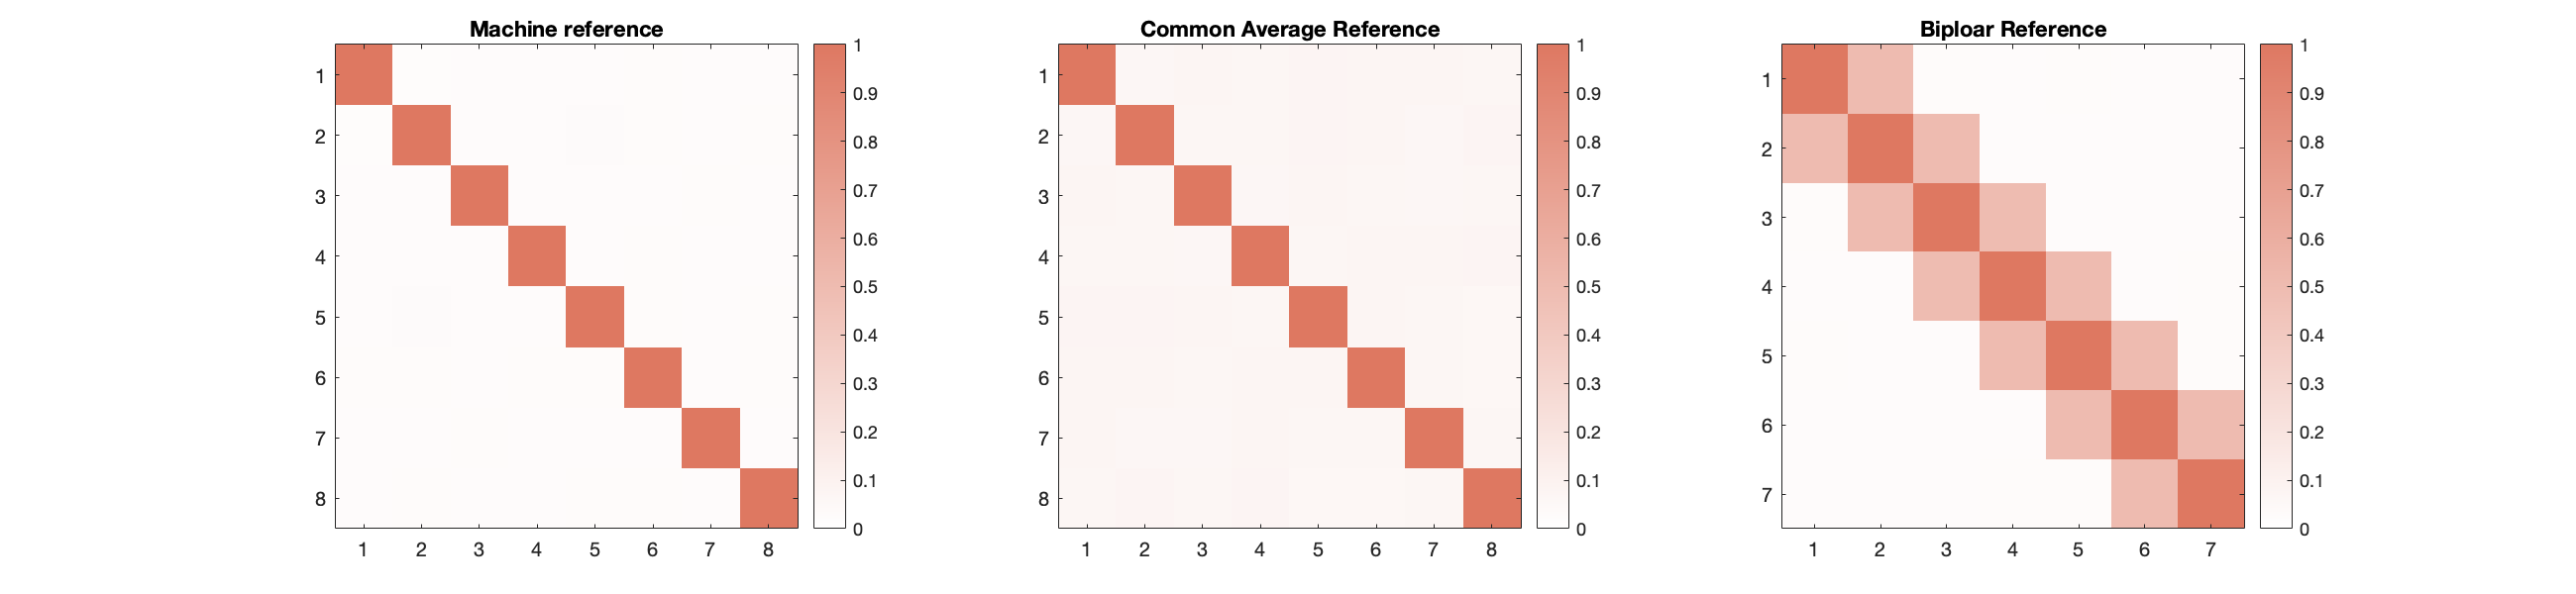

 
if exist(strcat(dataPath,'/spurcorr.mat'),'file') ~= 2
    error('No results file exist, please make sure to run section 4.')
else
    load(strcat(dataPath,'/spurcorr.mat'));
end
% imagesc plot
coh1plot = mean(coh1.cohspctrm,3);
coh2plot = mean(coh2.cohspctrm,3);
coh1bpplot = mean(coh1bp.cohspctrm,3);
coh2bpplot = mean(coh2bp.cohspctrm,3);
coh1carplot = mean(coh1car.cohspctrm,3);
coh2carplot = mean(coh2car.cohspctrm,3);

white = [1,1,1]; red = hex2rgb('#de7862');
colors = [white;red];
positions = [0, 1];
mycolormap = interp1(positions, colors, linspace(0, 1, 256), 'pchip');
% Customize the appearance of the heatmap
figure('Position',[0 0 1300 300]); 
subplot(1,3,1)
imagesc(coh1plot(1:8,1:8));colorbar;caxis([0,1]);
title('Machine reference')
subplot(1,3,2)
imagesc(coh1carplot(1:8,1:8));colorbar;caxis([0,1]);
title('Common Average Reference')
subplot(1,3,3)
imagesc(coh1bpplot(1:7,1:7));colorbar;caxis([0,1]);
title('Biploar Reference')
colormap(mycolormap);
exportgraphics(gcf, strcat(figPath,'/spurcorr1.png'), 'Resolution', 300);
saveas(gcf,strcat(figPath,'/spurcorr1.svg'))

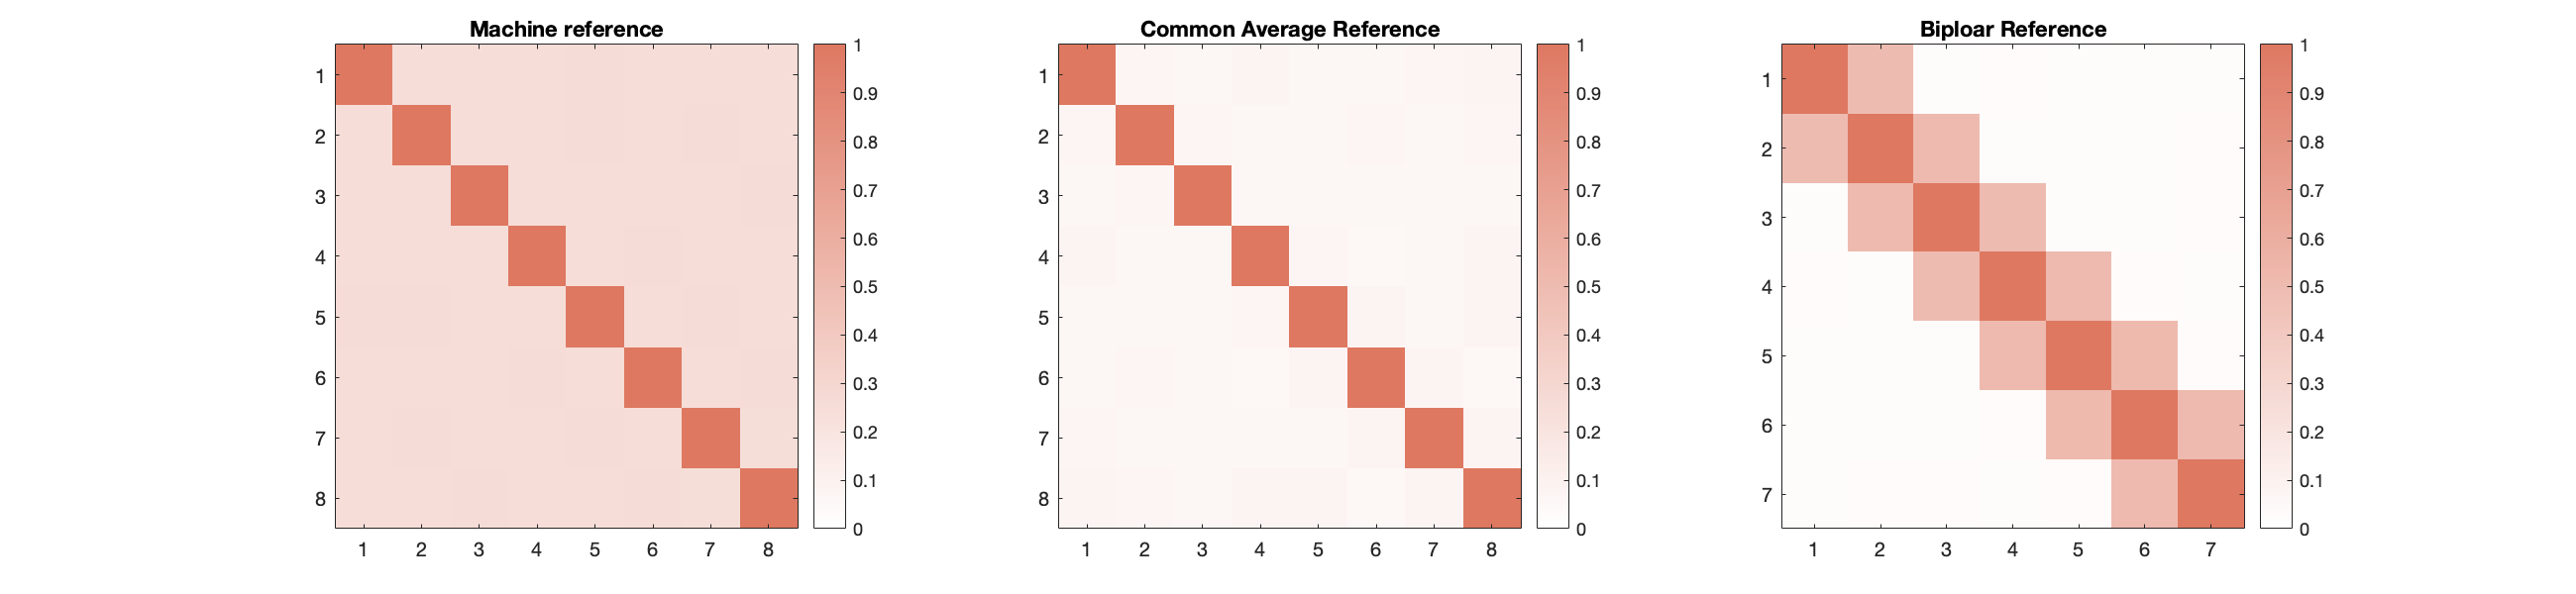

% without
figure('Position',[0 0 1300 300]); 
subplot(1,3,1)
imagesc(coh2plot(1:8,1:8));colorbar;caxis([0,1]);
title('Machine reference')
subplot(1,3,2)
imagesc(coh2carplot(1:8,1:8));colorbar;caxis([0,1]);
title('Common Average Reference')
subplot(1,3,3)
imagesc(coh2bpplot(1:7,1:7));colorbar;caxis([0,1]);
title('Biploar Reference')
colormap(mycolormap);
exportgraphics(gcf, strcat(figPath,'/spurcorr2.png'), 'Resolution', 300);
saveas(gcf,strcat(figPath,'/spurcorr2.svg'))

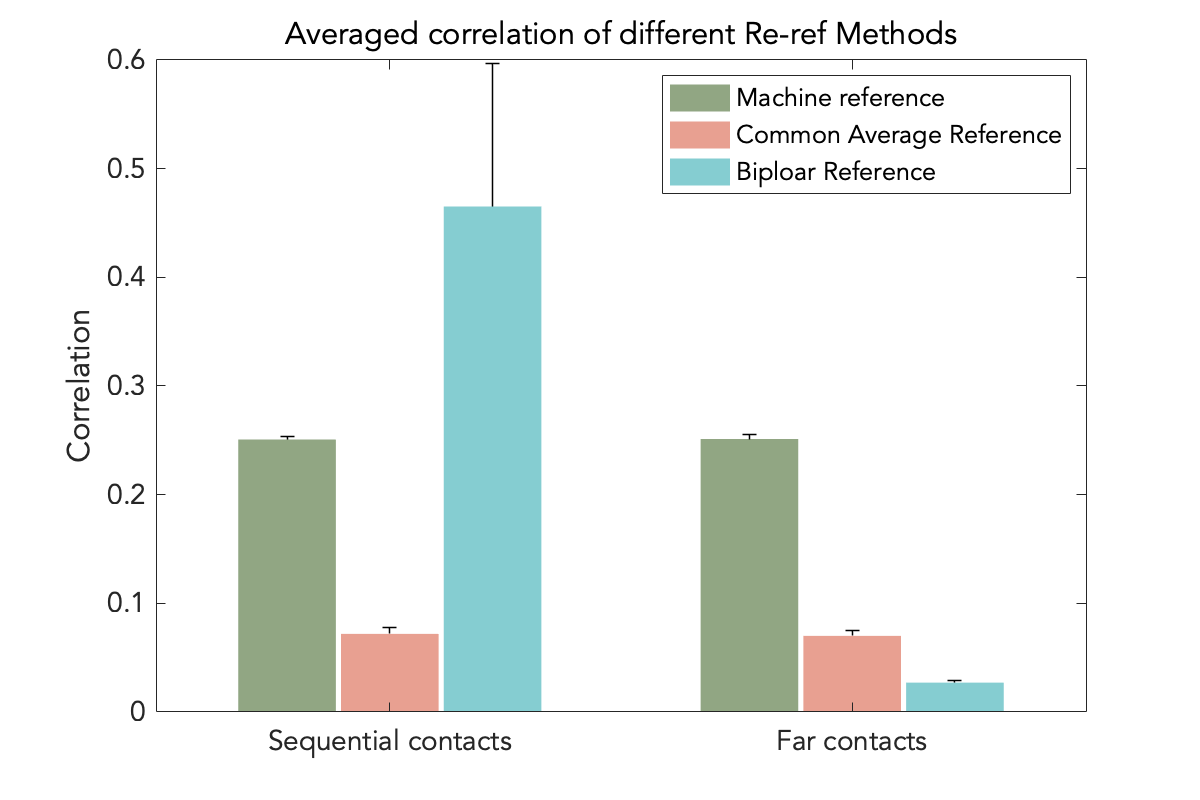

close all

% average plot
cols = {'#63804f','#de7862','#51b8bd'};
cols = hex2rgb(cols);
mycolormap = [reshape(cols,[1,3,3]);
              reshape(cols,[1,3,3])];

indbp1 = ~logical(triu(ones(14), 2))&logical(triu(ones(14), 1));
indbp2 = logical(triu(ones(14), 2));
indcar1 = ~logical(triu(ones(16), 2))&logical(triu(ones(16), 1));
indcar2 = logical(triu(ones(16), 2));
data = [mean(coh2plot(indcar1),'all'),mean(coh2carplot(indcar1),'all'),mean(coh2bpplot(indbp1),'all');
        mean(coh2plot(indcar2),'all'),mean(coh2carplot(indcar2),'all'),mean(coh2bpplot(indbp2),'all')];
error = [std(coh2plot(indcar1),0,'all'),std(coh2carplot(indcar1),0,'all'),std(coh2bpplot(indbp1),0,'all');
        std(coh2plot(indcar2),0,'all'),std(coh2carplot(indcar2),0,'all'),std(coh2bpplot(indbp2),0,'all')];
bar_error_plot(data,error,mycolormap,{'Sequential contacts','Far contacts'});
set(gcf,'Position',[0 0 600 400]);
legend({'Machine reference','Common Average Reference','Biploar Reference'})
title('Averaged correlation of different Re-ref Methods')
exportgraphics(gcf, strcat(figPath,'/spurcorr2_average.png'), 'Resolution', 300);
saveas(gcf,strcat(figPath,'/spurcorr2_average.svg'))

close all
if exist(strcat(dataPath,'/spurcorrconn.mat'),'file') ~= 2
    error('No results file exist, please make sure to run section 4.')
else
    load(strcat(dataPath,'/spurcorrconn.mat'));
end
broad_ind = [];tmp = 0;
for i = 1:nConn
    tmp = tmp+sum(numFeats(i));
    broad_ind = [broad_ind,tmp];
end
white = [1,1,1]; red = hex2rgb('#de7862');
colors = [white;red];
positions = [0, 1];
mycolormap = interp1(positions, colors, linspace(0, 1, 256), 'pchip');

for i = 1:nConn
    coh1plot = squeeze(mean(results1(:,1,broad_ind(i),:,:),1));
    coh2plot = squeeze(mean(results2(:,1,broad_ind(i),:,:),1));
    coh1bpplot = squeeze(mean(results1(:,3,broad_ind(i),:,:),1));
    coh2bpplot = squeeze(mean(results2(:,3,broad_ind(i),:,:),1));
    coh1carplot = squeeze(mean(results1(:,2,broad_ind(i),:,:),1));
    coh2carplot = squeeze(mean(results2(:,2,broad_ind(i),:,:),1));
    % without recording ref
    figure('Position',[0 0 1300 300]); 
    subplot(1,3,1)
    imagesc(coh1plot(1:8,1:8));colorbar;caxis([0,1]);
    title('Machine reference')
    subplot(1,3,2)
    imagesc(coh1carplot(1:8,1:8));colorbar;caxis([0,1]);
    title('Common Average Reference')
    subplot(1,3,3)
    imagesc(coh1bpplot(1:7,1:7));colorbar;caxis([0,1]);
    title('Biploar Reference')
    colormap(mycolormap);
    exportgraphics(gcf, strcat(figPath,'/spurcorr1_',connMeasures{i},'.png'), 'Resolution', 300);
    saveas(gcf,strcat(figPath,'/spurcorr1_',connMeasures{i},'.svg'))
    figure('Position',[0 0 1300 300]); 
    subplot(1,3,1)
    imagesc(coh2plot(1:8,1:8));colorbar;caxis([0,1]);
    title('Machine reference')
    subplot(1,3,2)
    imagesc(coh2carplot(1:8,1:8));colorbar;caxis([0,1]);
    title('Common Average Reference')
    subplot(1,3,3)
    imagesc(coh2bpplot(1:7,1:7));colorbar;caxis([0,1]);
    title('Biploar Reference')
    colormap(mycolormap);
    exportgraphics(gcf, strcat(figPath,'/spurcorr2_',connMeasures{i},'.png'), 'Resolution', 300);
    saveas(gcf,strcat(figPath,'/spurcorr2_',connMeasures{i},'.svg'))
    close all
end

## 5 | Sensitivity to electrode removal 📉

This part evaluate which method is most robust to sparse sampling

 
if exist(strcat(dataPath,'/results.mat'),'file') ~= 2
    error('No results file exist, please make sure to run section 2.')
else
    load(strcat(dataPath,'/results.mat'));
end
perc = [0.2 0.4 0.6 0.8];
n_trial = 1000;
permResult = NaN(size(results,1),nMethod,length(perc),n_trial,72);%for each patient X 48 methods X 3 percent X 500 trials  X n contacts
globalPermResult = NaN(nMethod,length(perc),n_trial,size(results,1));%for each method X 3 percent X 500 trials X 62 patients;
bar = waitbar(0, 'Processing...');
for i = 1:size(results,1)
    waitbar(i/size(results,1), bar, sprintf('Processing %d of %d...', i, size(results,1)));
    for k = 1:length(perc)
        for n = 1:n_trial
            tmp = results(i,:,:,:,:,:);
            tmp = reshape(tmp,[nRef,sum(numFeats),36,36,2]);
            for j = 1:2
                tmp(j,:,:,:,:) = remove_percent(squeeze(tmp(j,:,:,:,:)),perc(k));
            end
            tmp = permute(tmp,[2,1,3,4,5]);
            tmp = reshape(tmp,[nMethod,36,36,2]);
            nodeStr = [];
            for j = 1:36
                nodeStr(:,j,1) = mean(tmp(:,j,[1:(j-1),(j+1):end],1),3,'omitnan');
                nodeStr(:,j,2) = mean(tmp(:,j,[1:(j-1),(j+1):end],2),3,'omitnan');
            end
            nodeStr = reshape(nodeStr,[nMethod,36*2]);
            globalStr = mean(nodeStr,2,'omitnan');
            permResult(i,:,k,n,:) = nodeStr;
            globalPermResult(:,k,n,i) = globalStr;
        end
    end
end
close(bar)
permReliability = NaN(size(results,1),48,length(perc));% for each patient X 48 method X 3 percent has one reliability score;
var_error = nanmean(squeeze(nanstd(permResult,0,4).^2),4);
var_true = nanmean((nanstd(permResult,0,5).^2),4);
permReliability = var_true./(var_true + var_error);
save(strcat(dataPath,'/perm.mat'),'var_error','var_true','permReliability')
% global
var_true = repmat((nanmean(nanstd(globalPermResult,0,4).^2,3)),[1,1,size(results,1)]);
var_error = squeeze((nanstd(globalPermResult,0,3).^2));
globalReliability = var_true./(var_true+var_error);
globalReliability = permute(globalReliability,[3,1,2]);
save(strcat(dataPath,'/globalperm.mat'),'var_error','var_true','globalReliability')

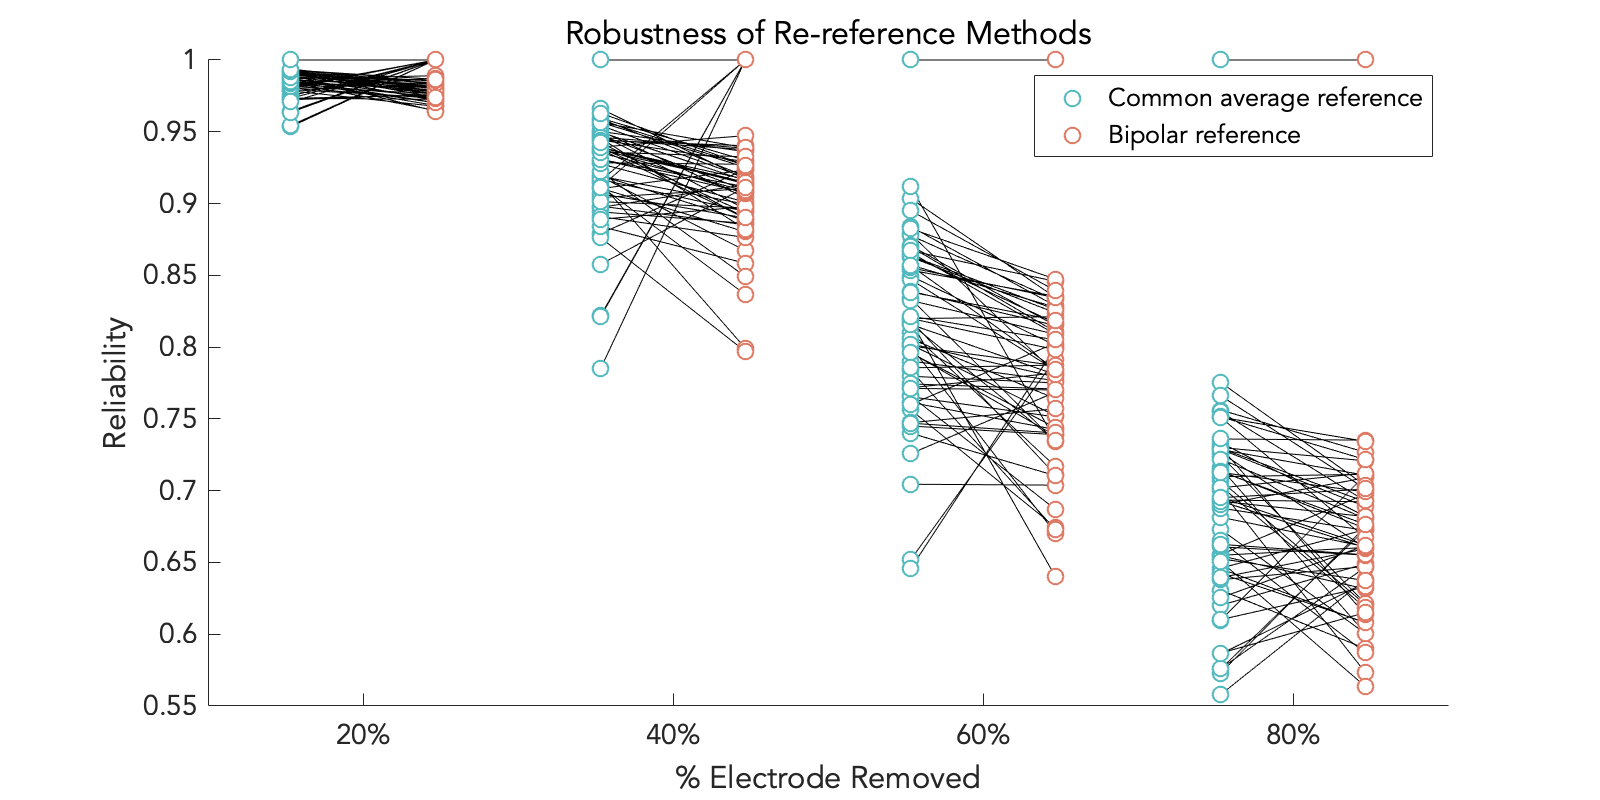

 
if exist(strcat(dataPath,'/perm.mat'),'file') ~= 2
    error('No results file exist, please make sure to run section 5.')
else
    load(strcat(dataPath,'/perm.mat'));
    load(strcat(dataPath,'/globalperm.mat'))
end

%% SPLIT BY REF
% plot
ref = reshape(permReliability,[size(permReliability,1),sum(numFeats),nRef,size(permReliability,3)]);
ref = squeeze(nanmean(ref,2));
for i = 1:nRef
    boxdata{i} = squeeze(ref(:,i,:));
end
plot_paired_line(boxdata);
title('Robustness of Re-reference Methods','FontSize',16,'FontWeight','bold','FontName','Avenir')
exportgraphics(gcf, strcat(figPath,'/robustRef_line.png'), 'Resolution', 300);
saveas(gcf,strcat(figPath,'/robustRef_line.svg'))

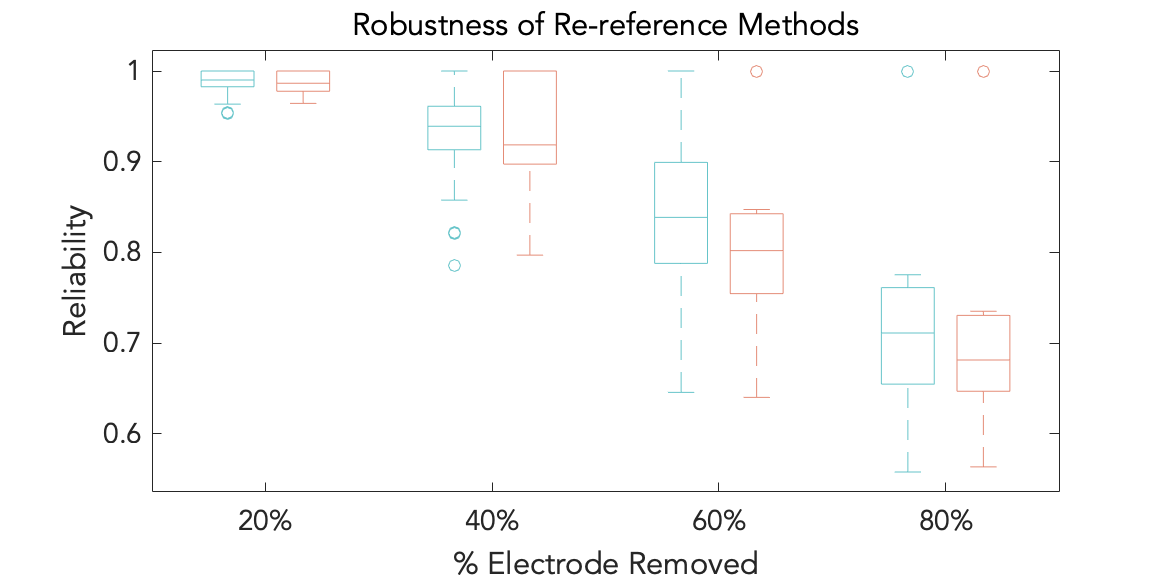

close all
% box plot
groupCenters = @(nGroups,nMembers,interGroupSpace) ...
    nGroups/2+.5 : nGroups+interGroupSpace : (nGroups+interGroupSpace)*nMembers-1;
red = hex2rgb('#de7862');blue = hex2rgb('#51b8bd');
col = brighten([blue;red],0.2);
fig = figure('Position',[0,0,800,400]);
hold on
b = boxplotGroup(boxdata,'primaryLabels',{'',''}, ...
    'Colors',col,'GroupType','betweenGroups', ...
    'PlotStyle','traditional','BoxStyle','outline', ...
    'Symbol','o','Widths',0.7);
title('Robustness of Re-reference Methods','FontSize',16,'FontWeight','bold')
ylabel('Reliability')
xlabel('% Electrode Removed')
set(gca,'FontName','Avenir','FontSize',14)
ticks = groupCenters(numel(boxdata), size(boxdata{1},2), 1);
set(gca,'XTick',ticks,'XTickLabels',{'20%','40%','60%','80%'})
exportgraphics(gcf, strcat(figPath,'/robustRef.png'), 'Resolution', 300);
saveas(gcf,strcat(figPath,'/robustRef.svg'))

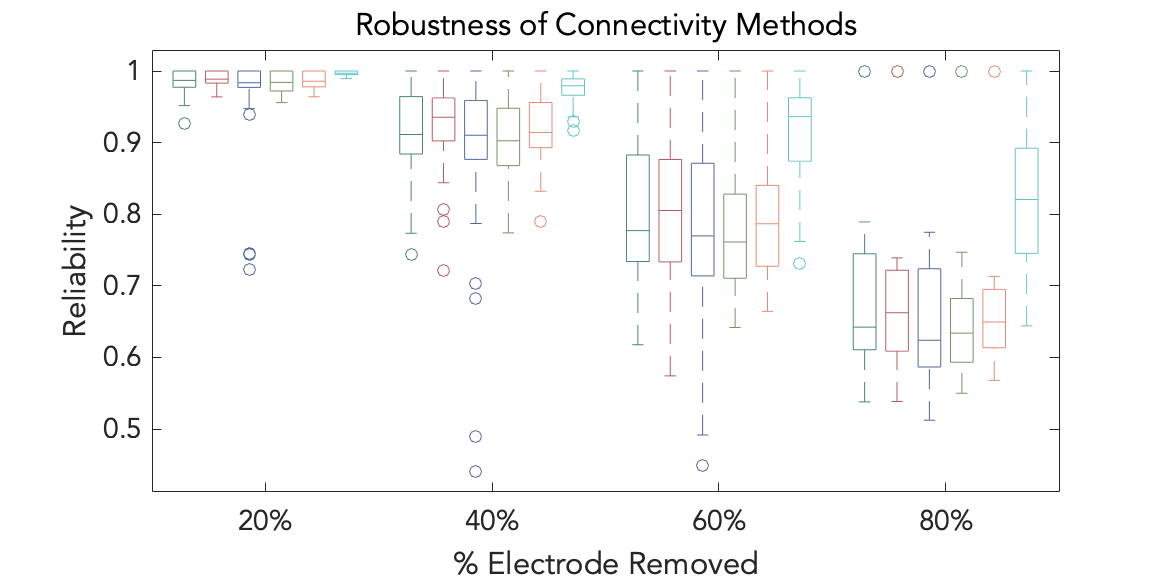

close all
%% SPlit by method
for i = 1:nConn
    tmp = permReliability(:,sum(numFeats(1:i-1))+1:sum(numFeats(1:i)),:);
    tmp = (tmp + permReliability(:,sum(numFeats(1:i-1))+1+24:sum(numFeats(1:i))+24,:))/2;
    method(:,i,:) = nanmean(tmp,2);
    boxdata{i} = squeeze(method(:,i,:));
end
dark_cols = {'#63804f','#de7862','#51b8bd','#367068','#a5474e','#3c5488'};
dark_cols = hex2rgb(dark_cols);
dark_cols = dark_cols([4,5,6,1,2,3],:);
dark_cols = brighten(dark_cols,0.2);
figure('Position',[0,0,800,400])
hold on
b = boxplotGroup(boxdata,'primaryLabels',{'','','','','',''}, ...
    'Colors',dark_cols,'GroupType','betweenGroups', ...
    'PlotStyle','traditional','BoxStyle','outline', ...
    'Symbol','o','Widths',0.7);
title('Robustness of Connectivity Methods','FontSize',16,'FontWeight','bold')
ylabel('Reliability')
xlabel('% Electrode Removed')
set(gca,'FontName','Avenir','FontSize',14)
ticks = groupCenters(numel(boxdata), size(boxdata{1},2), 1);
set(gca,'XTick',ticks,'XTickLabels',{'20%','40%','60%','80%'})
exportgraphics(gcf, strcat(figPath,'/robustMethod.png'), 'Resolution', 300);
saveas(gcf,strcat(figPath,'/robustMethod.svg'))

close all
%% SPlit by freq
ini = [];


ini =

     []



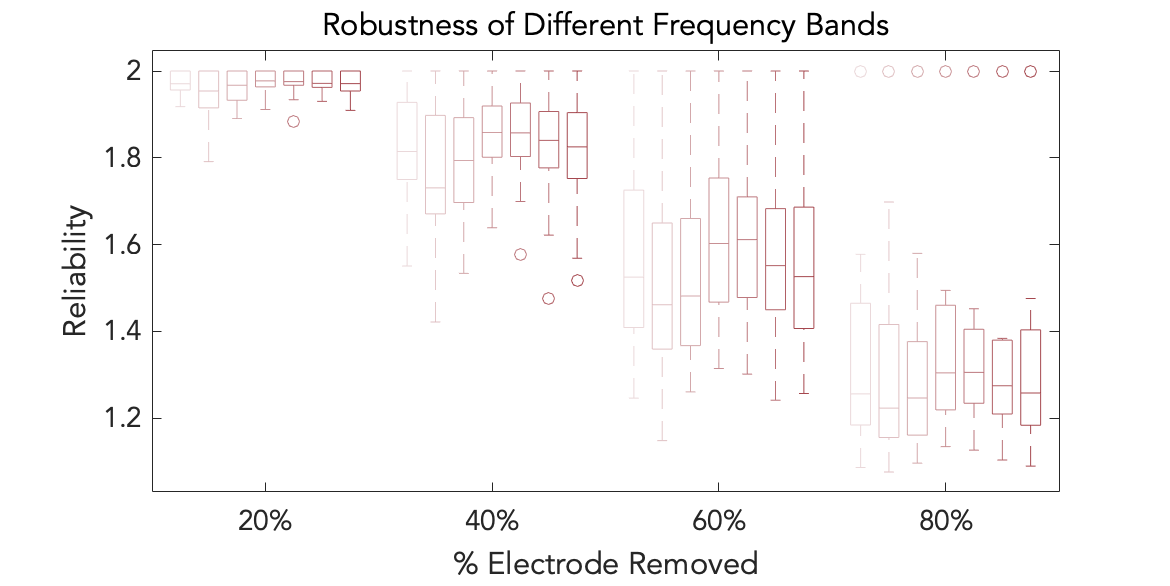

for i = 1:nConn
    if numFeats(i) == 1
        continue
    else
        ini = [ini, sum(numFeats(i-1))];
    end
end
for i = 1:nFreq
    tmp = permReliability(:,ini+i,:);
    tmp = tmp + permReliability(:,ini+i+sum(numFeats),:);
    freq(:,i,:) = nanmean(tmp,2);
    boxdata{i} = squeeze(freq(:,i,:));
end
dark = hex2rgb('#a5474e');
bright = hex2rgb('#ead8da');
position = [0,1];
mycolormap = interp1(position, [bright;dark], linspace(0, 1, 7), 'pchip');
figure('Position',[0,0,800,400])
hold on
b = boxplotGroup(boxdata,'primaryLabels',{'','','','','','',''}, ...
    'Colors',mycolormap,'GroupType','betweenGroups', ...
    'PlotStyle','traditional','BoxStyle','outline', ...
    'Symbol','o','Widths',0.7);
title('Robustness of Different Frequency Bands','FontSize',16,'FontWeight','bold')
ylabel('Reliability')
xlabel('% Electrode Removed')
set(gca,'FontName','Avenir','FontSize',14)
ticks = groupCenters(numel(boxdata), size(boxdata{1},2), 1);
set(gca,'XTick',ticks,'XTickLabels',{'20%','40%','60%','80%'})
exportgraphics(gcf, strcat(figPath,'/robustFreq.png'), 'Resolution', 300);
saveas(gcf,strcat(figPath,'/robustFreq.svg'))

close all
%stats
tref = reshape(permute(ref,[1,3,2]),size(ref,1)*size(ref,3),nRef);
tmethod = reshape(permute(method,[1,3,2]),size(method,1)*size(method,3),nConn);
tfreq = reshape(permute(freq,[1,3,2]),size(freq,1)*size(freq,3),nFreq);
[p,tbl,stats] = friedman(tfreq,76);
cfreq = multcompare(stats);
[p,tbl,stats] = friedman(tref,76);
cref = multcompare(stats);
[p,tbl,stats] = friedman(tmethod,76);
cmethod = multcompare(stats);
save(strcat(dataPath,'/permstats.mat'),'tref','tfreq','tmethod','cfreq','cref','cmethod');

## 6 | SOZ lateralization 🧠

This part evaluate which method perform best in lateralizing epilepsy patients.

(Note: The ML part was implemented in Google Colab and hasn't been transfered to here yet) 

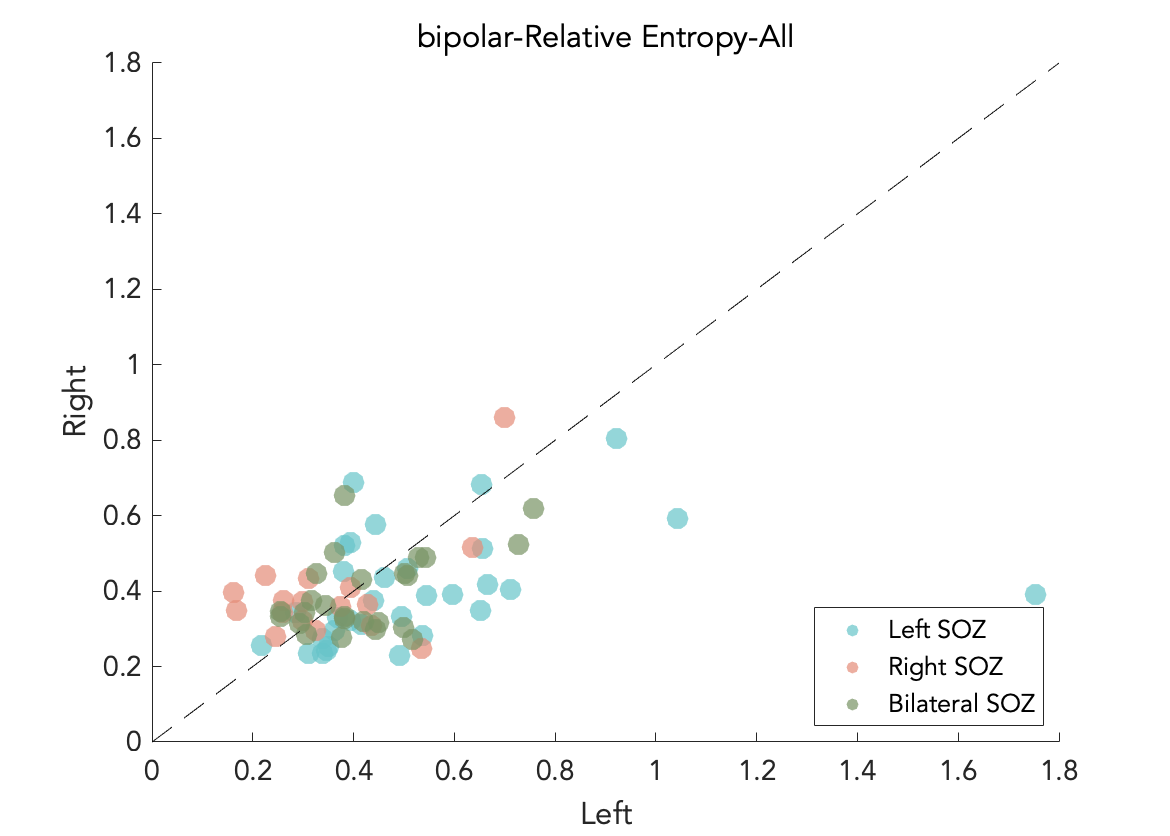

%% export machine learning data
 
if exist(strcat(dataPath,'/results.mat'),'file') ~= 2
    error('No results file exist, please make sure to run section 2.')
else
    load(strcat(dataPath,'/results.mat'));
end
ind = find(triu(ones(36,36), 1));
for i = 1:size(results,1)
    tmp = results(i,:,:,:,:,:);
    tmp = reshape(tmp,[length(refMethods),sum(numFeats),36,36,2]);
    tmp = permute(tmp,[2,1,3,4,5]);
    tmp = reshape(tmp,[length(refMethods)*sum(numFeats),36,36,2]);
    nodeStr = [];
    for j = 1:36
        nodeStr(:,j,1) = nanmean(tmp(:,j,[1:(j-1),(j+1):end],1),3);
        nodeStr(:,j,2) = nanmean(tmp(:,j,[1:(j-1),(j+1):end],2),3);
    end
    nodeStrAll(i,:,:,:) = nodeStr;

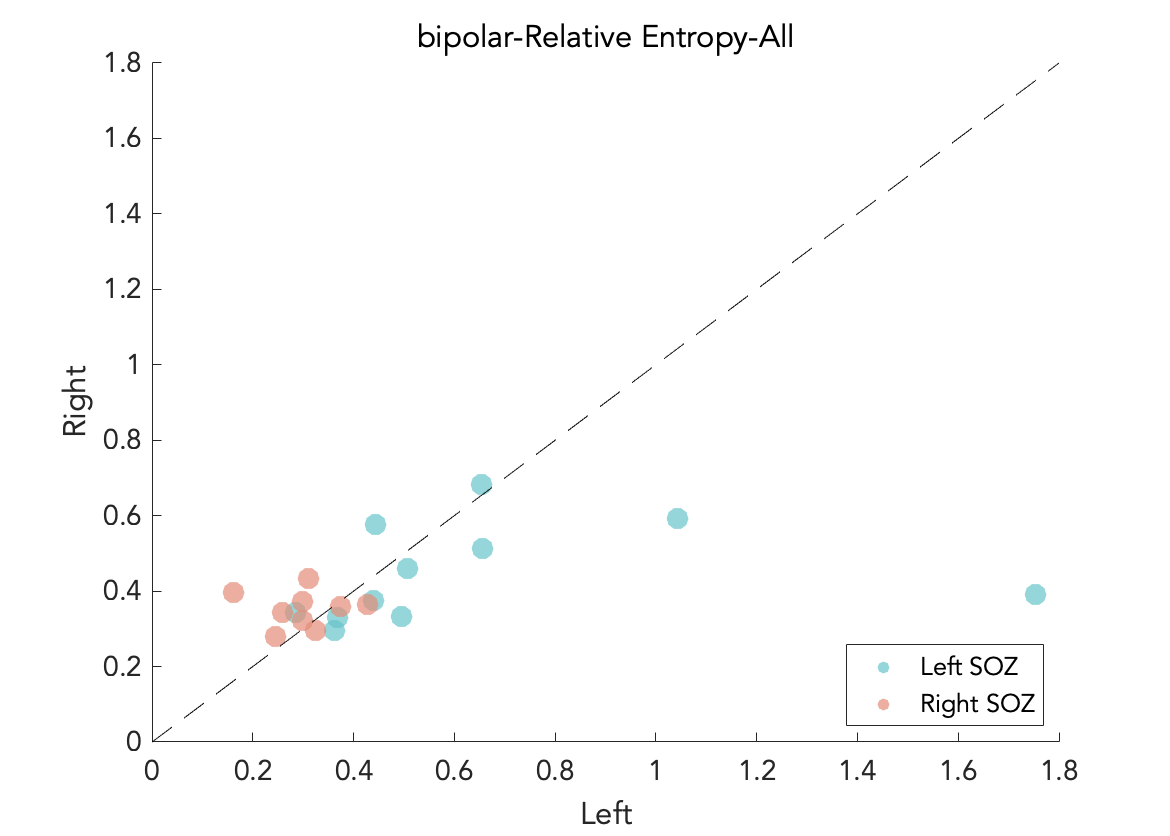

end

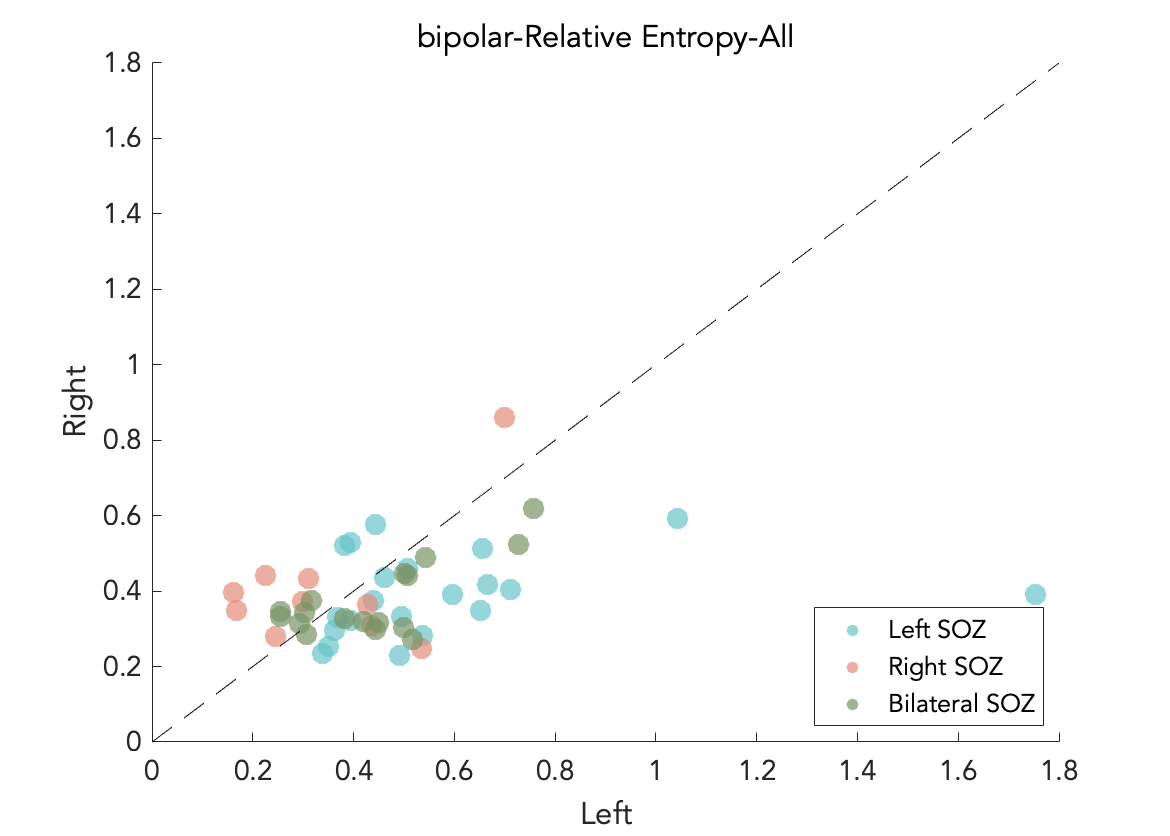

nodeStrAll = squeeze(nanmean(nodeStrAll,3));

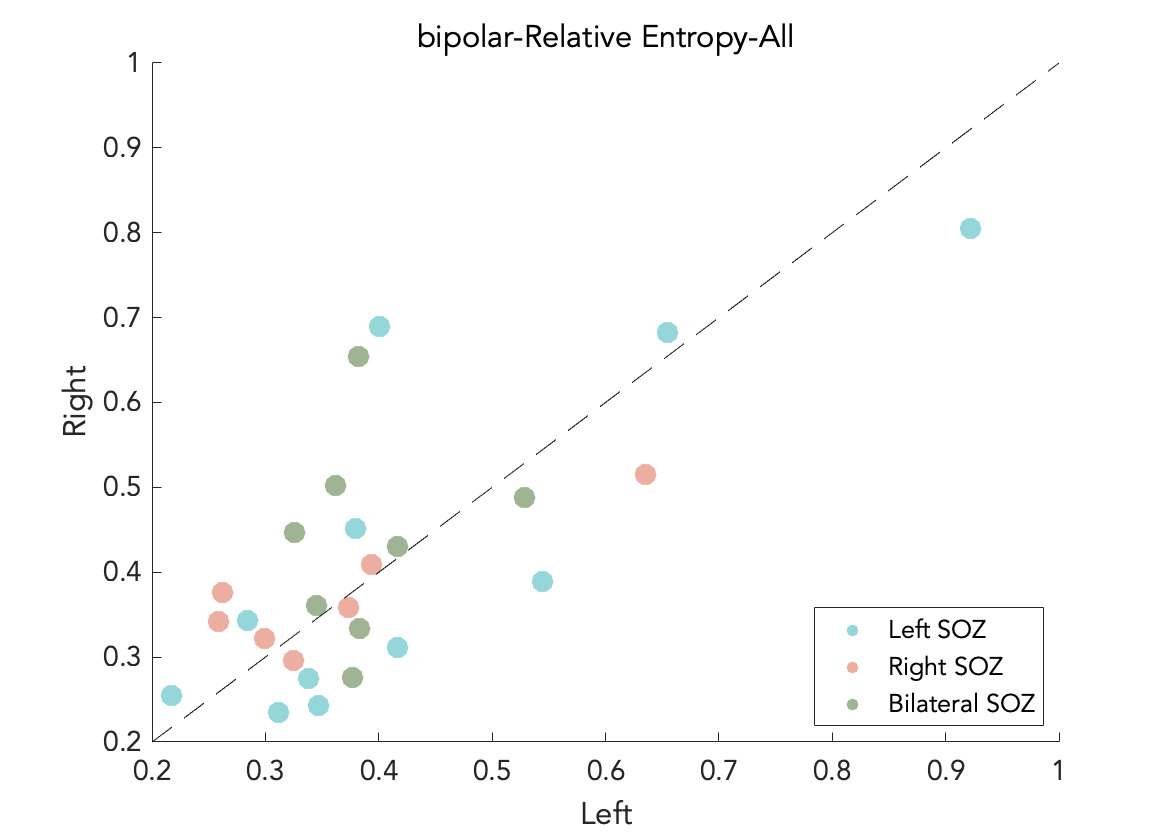

% build labels

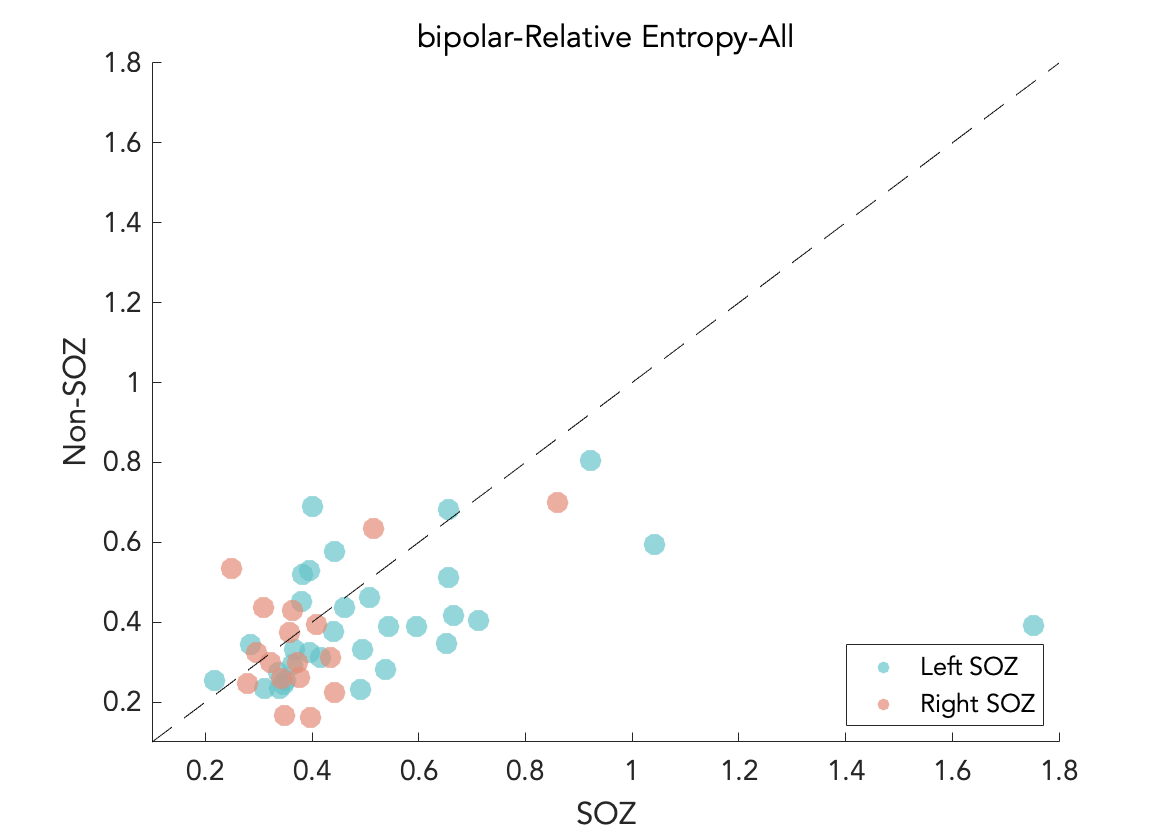

strlabel = {patientList.soz}';
istemp = [patientList.istemp];

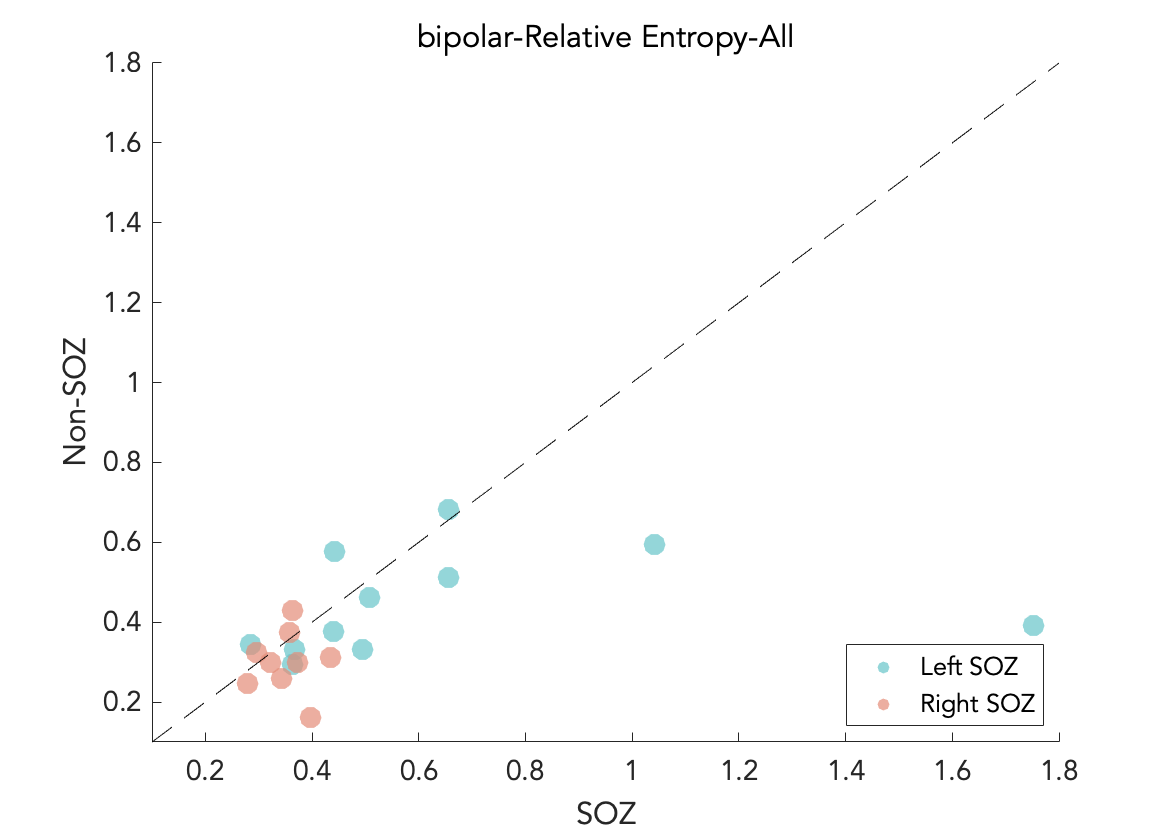

strlabel(~logical(keep)) = [];

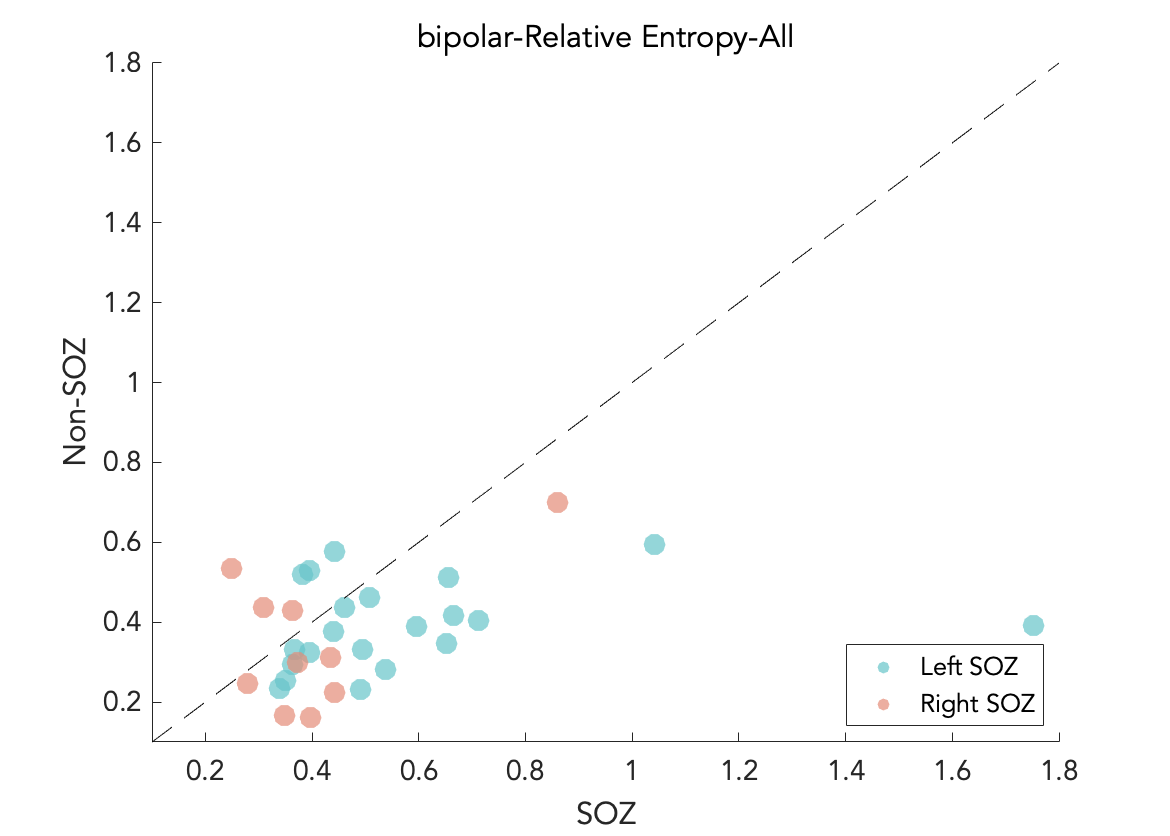

istemp(~logical(keep)) = [];

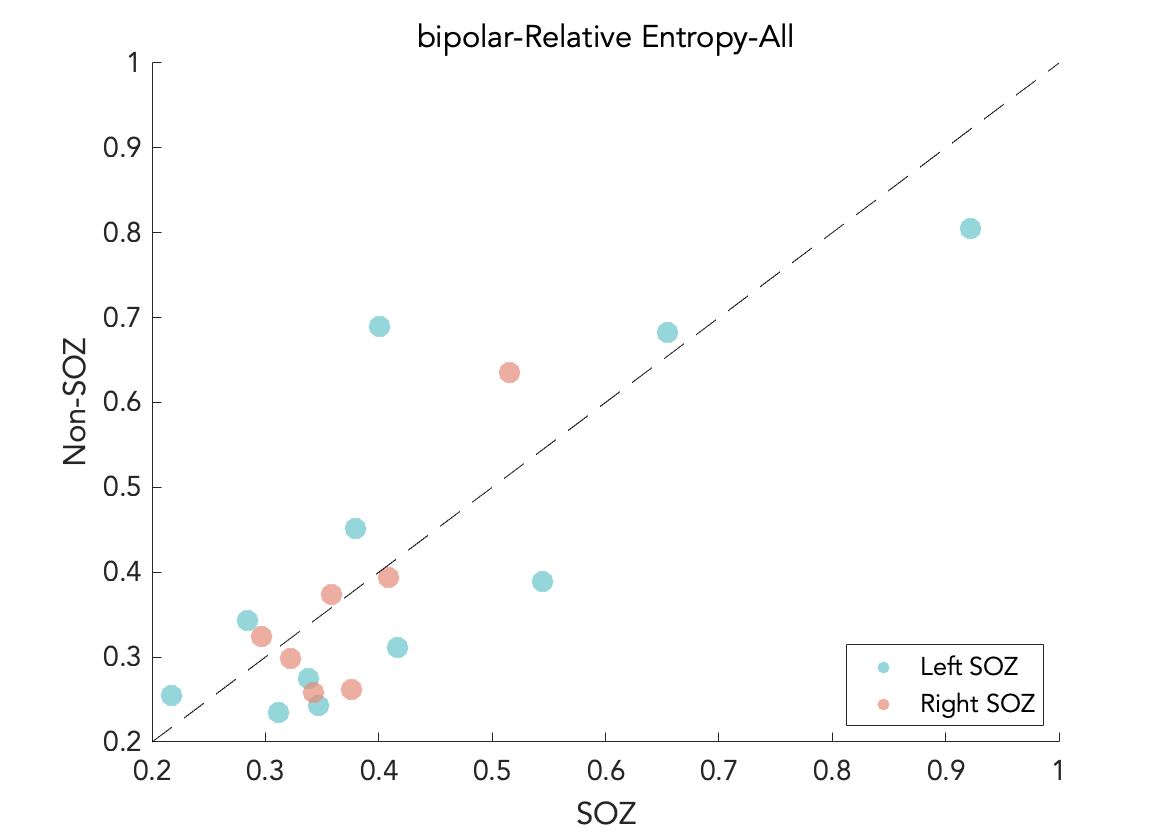

numlabel = zeros(length(strlabel),1);

numlabel(cellfun(@(x) strcmp(x,'left'),strlabel)) = 1;
numlabel(cellfun(@(x) strcmp(x,'right'),strlabel)) = 2;
numlabel(cellfun(@(x) strcmp(x,'bilateral'),strlabel)) = 3;
remove = find(numlabel==0);
numlabel(remove) = [];
strlabel(remove) = [];
nodeStrAll(remove,:,:) = [];
istemp(remove) = [];
istemp = logical(istemp');
goodoutcome = cellfun(@(x) ~isempty(x)&&x < 2,{patientList.Engel});
goodoutcome(~logical(keep)) = [];
goodoutcome(remove) = [];
goodoutcome = goodoutcome';
nodeStrAll = permute(nodeStrAll,[2,1,3]);
save(strcat(dataPath,'/sozML.mat'),'nodeStrAll','numlabel','strlabel','istemp','goodoutcome')
for k = 1:nMethod
    eval(['writematrix(squeeze(nodeStrAll(',num2str(k),',:,:)),strcat(MLPath,"/',num2str(k),'",".csv"));']);
end
writematrix(numlabel,strcat(MLPath,'/label.csv'))
% freqBands = {'delta','theta','alpha','beta','gamma','ripple','broad'};
colNames = {};
for i = 1:length(connMeasureNames)
    if numFeats(i) == 1
        colNames = [colNames, connMeasureNames(i)];
    elseif numFeats(i) == nFreq
         tmpNames = strcat(connMeasureNames(i),{'-'},freqBandNames);
        colNames = [colNames, tmpNames];
    end
end
finalNames = [strcat(refMethods{1},'-',colNames),strcat(refMethods{2},'-',colNames)];
writecell(finalNames,strcat(MLPath,'/methods.csv'))
% output patient list
writematrix(goodoutcome,strcat(MLPath,'/goodout.csv'))

% if there's left vs right difference overall
% meanL,meanR,mean(L-R),mean(L-R/R),pvalue
extractMLData(nodeStrAll,strcat(MLPath,'/pairT_LR.csv'));
% how the difference change in left/right/bilateral patients
extractMLData(nodeStrAll(:,numlabel==1,:),strcat(MLPath,'/pairT_LR_sozL.csv'));
extractMLData(nodeStrAll(:,numlabel==2,:),strcat(MLPath,'/pairT_LR_sozR.csv'));
extractMLData(nodeStrAll(:,numlabel==3,:),strcat(MLPath,'/pairT_LR_sozB.csv'));
% per-method left-right scatter plot
extractMLData(nodeStrAll(:,goodoutcome,:),strcat(MLPath,'/pairT_LR_good.csv'));
extractMLData(nodeStrAll(:,goodoutcome&numlabel==1,:),strcat(MLPath,'/pairT_LR_good_sozL.csv'));
extractMLData(nodeStrAll(:,goodoutcome&numlabel==2,:),strcat(MLPath,'/pairT_LR_good_sozR.csv'));
% per-method temporal lobe/nontempraol lobe
extractMLData(nodeStrAll(:,istemp,:),strcat(MLPath,'/pairT_LR_temp.csv'));
extractMLData(nodeStrAll(:,istemp&numlabel==1,:),strcat(MLPath,'/pairT_LR_temp_sozL.csv'));
extractMLData(nodeStrAll(:,istemp&numlabel==2,:),strcat(MLPath,'/pairT_LR_temp_sozR.csv'));
extractMLData(nodeStrAll(:,~istemp,:),strcat(MLPath,'/pairT_LR_nontemp.csv'));
extractMLData(nodeStrAll(:,~istemp&numlabel==1,:),strcat(MLPath,'/pairT_LR_nontemp_sozL.csv'));
extractMLData(nodeStrAll(:,~istemp&numlabel==2,:),strcat(MLPath,'/pairT_LR_nontemp_sozR.csv'));
% soz/non-soz difference, pair-ttest
nodeStrAll(:,numlabel==2,:) = nodeStrAll(:,numlabel==2,[2,1]);
extractMLData(nodeStrAll(:,numlabel==1|numlabel==2,:),strcat(MLPath,'/pairT_SOZ.csv'));
extractMLData(nodeStrAll(:,numlabel==1,:),strcat(MLPath,'/pairT_SOZ_sozL.csv'));
extractMLData(nodeStrAll(:,numlabel==2,:),strcat(MLPath,'/pairT_SOZ_sozR.csv'));
% goodoutcome
extractMLData(nodeStrAll(:,goodoutcome,:),strcat(MLPath,'/pairT_SOZ_good.csv'));
extractMLData(nodeStrAll(:,goodoutcome&numlabel==1,:),strcat(MLPath,'/pairT_SOZ_good_sozL.csv'));
extractMLData(nodeStrAll(:,goodoutcome&numlabel==2,:),strcat(MLPath,'/pairT_SOZ_good_sozR.csv'));
% temporal lobe
extractMLData(nodeStrAll(:,istemp&(numlabel==1|numlabel==2),:),strcat(MLPath,'/pairT_SOZ_temp.csv'));
extractMLData(nodeStrAll(:,istemp&numlabel==1,:),strcat(MLPath,'/pairT_SOZ_temp_sozL.csv'));
extractMLData(nodeStrAll(:,istemp&numlabel==2,:),strcat(MLPath,'/pairT_SOZ_temp_sozR.csv'));
extractMLData(nodeStrAll(:,~istemp&(numlabel==1|numlabel==2),:),strcat(MLPath,'/pairT_SOZ_nontemp.csv'));
extractMLData(nodeStrAll(:,~istemp&numlabel==1,:),strcat(MLPath,'/pairT_SOZ_nontemp_sozL.csv'));
extractMLData(nodeStrAll(:,~istemp&numlabel==2,:),strcat(MLPath,'/pairT_SOZ_nontemp_sozR.csv'));

 
if exist(strcat(dataPath,'/sozML.mat'),'file') ~= 2
    error('No results file exist, please make sure to run section 6.')
else
    load(strcat(dataPath,'/sozML.mat'));
end
colNames = {};
for i = 1:length(connMeasureNames)
    if numFeats(i) == 1
        colNames = [colNames, connMeasureNames(i)];
    elseif numFeats(i) == 7
         tmpNames = strcat(connMeasureNames(i),{'-'},freqBands);
        colNames = [colNames, tmpNames];
    end
end
global finalNames
finalNames = [strcat(refMethods{1},'-',colNames),strcat(refMethods{2},'-',colNames)];
plot_soz_scatter(nodeStrAll,numlabel,'pairT_LR');
plot_soz_scatter(nodeStrAll(:,goodoutcome,:),numlabel(goodoutcome),'pairT_LR_good');
plot_soz_scatter(nodeStrAll(:,istemp,:),numlabel(istemp),'pairT_LR_temp');
plot_soz_scatter(nodeStrAll(:,~istemp,:),numlabel(~istemp),'pairT_LR_nontemp');
nodeStrAll(:,numlabel==2,:) = nodeStrAll(:,numlabel==2,[2,1]);
plot_soz_scatter(nodeStrAll(:,numlabel==1|numlabel==2,:),numlabel(numlabel==1|numlabel==2),'pairT_SOZ');
plot_soz_scatter(nodeStrAll(:,goodoutcome,:),numlabel(goodoutcome),'pairT_SOZ_good');
plot_soz_scatter(nodeStrAll(:,istemp'&(numlabel==1|numlabel==2),:),numlabel(istemp'&(numlabel==1|numlabel==2)),'pairT_SOZ_temp');
plot_soz_scatter(nodeStrAll(:,~istemp'&(numlabel==1|numlabel==2),:),numlabel(~istemp'&(numlabel==1|numlabel==2)),'pairT_SOZ_nontemp');
% volcano plot
files = dir(strcat(MLPath,'/pairT*'));
for i = 1:length(files)
    volcano_process(files(i).name(1:end-4));
end